%% Demo: SingleGeneratorDynamic salient-pole SMIB--linear-AVR identification
% Low-dimensional power-system case for the PhDN manuscript.
%
% The selected model is a four-state salient-pole single-machine infinite-bus
% system with flux decay, reluctance power, unequal d/q voltage channels, and
% a linear AVR. It is written in explicit standard ODE
% form, xdot=f(x): all conventional derivative coefficients (2H, T'_do, T_A)
% are divided into the right-hand sides.
%
% This demo extends the Feynman Stage-0/1/2 framework with:
%   1) a nested scrambled-Sobol training sweep Ntrain={500,1000,2500,5000};
%   2) independent fixed scrambled-Sobol validation/ID-test/OOD sets;
%   3) vector-field/derivative RMSE;
%   4) hard joint-OOD initial-condition rollout RMSE;
%   5) active coefficient/parameter count and complete training time;
%   6) sample-efficiency and representative trajectory figures.

clear; clc;
rng(1);

casemode = 'general';            
caseToRun = 'SMIB_AVR';
TrainingSampleList = [250,500,1000,2000];

assert(all(diff(TrainingSampleList)>0), ...
    'TrainingSampleList must be strictly increasing for nested sample-model comparisons.');
NValidationSamples = 500;
NIDTestSamples = 1000;
NumRounds = 1;                   % increase for manuscript mean/std statistics
RoundRandomStateStride = 1;

% Scrambled-Sobol sampling policy.  Every Ntrain uses a prefix of one fixed
% 5000-point training master pool. Validation, ID-test, and OOD use independent
% scrambles and remain fixed across the Ntrain sweep within each round.
SamplingMethod = 'scrambled_sobol';
SobolScrambleMethod = 'MatousekAffineOwen';
SobolSkip = 1024;
MaxTrainingSamples = max(TrainingSampleList);
BaseTrainPoolSeed = 7301;
BaseValidationPoolSeed = 7401;
BaseTestPoolSeed = 7501;
BaseOODPoolSeed = 8501;

projectRoot = pwd;
if ~exist(fullfile(projectRoot,'core'),'dir') || ~exist(fullfile(projectRoot,'tasks'),'dir')
    try
        activeFile = matlab.desktop.editor.getActiveFilename;
        projectRoot = fileparts(activeFile);
    catch
        error('Cannot locate the project root. Set the current folder to the framework root.');
    end
end
addpath(genpath(projectRoot));
% Prefer canonical project-root implementations over any stale patch-wrapper
% folders that may also be included by genpath.
addpath(fullfile(projectRoot,'system_identification'),'-begin');
addpath(fullfile(projectRoot,'baselines','eql'),'-begin');
clear plot_single_generator_dynamic_trajectory ...
    plot_system_identification_sample_efficiency;
rehash;

% Case-local output tree. Per-sample checkpoints are saved immediately after
% each N/round finishes, so completed runs survive a later baseline failure.
OutputCaseRoot = fullfile(projectRoot,'outputs','SingleGeneratorDynamic_SMIB_AVR');
OutputSummaryDir = fullfile(OutputCaseRoot,'summary');
if exist(OutputSummaryDir,'dir') ~= 7; mkdir(OutputSummaryDir); end

% -------------------------------------------------------------------------
% Plot-only fast path.
% When enabled, the demo skips all case verification, training, saved-model
% replay, rollout evaluation, and summary regeneration. It only loads the
% previously saved slim public summary MAT-file and redraws/export the paper
% figures requested below.
% -------------------------------------------------------------------------
RegeneratePaperFiguresOnly = false;
PaperFigureSourceResultsFile = fullfile(OutputSummaryDir,'public_summary.mat');
LegacyPaperFigureSourceResultsFile = fullfile(OutputSummaryDir,'single_generator_dynamic_results.mat');
if exist(PaperFigureSourceResultsFile,'file') ~= 2 && ...
        exist(LegacyPaperFigureSourceResultsFile,'file') == 2
    migrate_system_identification_summary_to_public( ...
        LegacyPaperFigureSourceResultsFile,PaperFigureSourceResultsFile, ...
        'DeleteLegacy',true);
end
PaperFigureExportDir = OutputSummaryDir;
PaperFigureVisible = true;
PaperFigureExportPDF = true;

if RegeneratePaperFiguresOnly
    paperFigureInfo = regenerate_single_generator_dynamic_paper_figures( ...
        PaperFigureSourceResultsFile,PaperFigureExportDir, ...
        'Visible',PaperFigureVisible,'ExportPDF',PaperFigureExportPDF);
    fprintf('\nSingleGeneratorDynamic plot-only regeneration finished.\n');
    fprintf('Source summary MAT: %s\n',paperFigureInfo.sourceResultsFile);
    fprintf('Export directory   : %s\n',paperFigureInfo.exportDir);
    for iPaperFigure = 1:numel(paperFigureInfo.figures)
        fprintf('Generated figure %d: %s\n',iPaperFigure, ...
            paperFigureInfo.figures(iPaperFigure).pdfPath);
    end
    return;
end

CaseSimulationWallTimer = tic;

% Cheap case-local preflight before any expensive PySR call.
verify_single_generator_dynamic_case_setup( ...
    task_single_generator_dynamic(caseToRun,casemode));

SingleGeneratorDynamic case-local mapping verified: x1=delta, x2=domega, x3=Eqp, x4=Efd
Model variant: salient_pole_flux_decay_linear_avr
Equilibrium max |RHS| = 0.000e+00
Saliency Ksal = -0.47619 | linear AVR gain KA = 10
Rollout IC design verified: hard joint delta-Eqp-Efd OOD with y4/terminal-voltage excitation.



############################################################


SingleGeneratorDynamic round 1/1 | PySR state=1 | MLP seed=1


############################################################


MLP sweep: width=64, depth=[2  3  4  5  6], activations={tanh,relu,silu}, depthEarlyStop=1


KAN sweep: width=8, depth=[2  3  4  5  6], sparse lambda=[1e-05      0.0001       0.001], grid patience=2, grid tolerance=1.50%, depth lookahead=1, pruneGuard=1


EQL sweep: depth=[2  3  4  5], lambda=[1e-05       0.001], depthEarlyStop=1


Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=250 | Nval=500 | Ntest=1000 | round=1


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test/OOD pools


Sobol scramble=MatousekAffineOwen | skip=1024 | seeds train/val/test/OOD=7301/7401/7501/8501


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=24


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=250; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


State/output normalization=0; rollout solver=ode4, horizon=2.00 s, dt=0.005 s, output times=401, ICs=5


Rollout IC box: lb=[1.18      -0.015        0.58        2.75], ub=[1.32       0.015         0.7           3], representative=[1.28       0.012        0.62         2.9], seed=9301


Rollout guards: max|x|=[10   1  10  20], max|dx/dt|=1e+04, RHS cap=1604, integration/method wall caps=600.0/180.0 s, abort after 3 consecutive failures


Rollout IC shift: joint delta-Eqp-Efd OOD emphasizing terminal-voltage and y4 dynamics | source=SMIB_salient_linear_AVR_joint_voltage_channel_OOD_IC_box


PhDN y4 prior-level ablation (outer coefficients are data-regression initializations):


  PhDN-G1 | 70-10*x4-43*sqrt(square(x3)+square(x1))
  PhDN-G2 | 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))
  PhDN-G3 | 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


SINDy matched prior source: PhDN-G3 only.



RECORDED METHOD REPLAY: PhDN-G1 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00250\method_results\phdn_g1.mat
Replay load: 5.451 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 4.510525e-05
  true-operator PhDN Test MSE = 2.045565e-05, RMSE = 4.522792e-03
  OOD true-operator PhDN Test MSE = 4.552240e-02, RMSE = 2.133598e-01
  active terms             : 526
  inv / exp / sqrt / cross : 0 / 0 / 5 / 216
  identity-can

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Validation MSE/RMSE            : 2.717301e-03 / 5.212773e-02
In-distribution test MSE/RMSE  : 1.303195e-03 / 3.609980e-02
OOD test MSE/RMSE              : 5.251083e-01 / 7.246436e-01
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 869.800 s
Native PySR search time        : 868.824 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: PhDN-G2 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00250\method_results\phdn_g2.mat
Replay load: 5.363 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.593158e-06
  true-operator PhDN Test MSE = 1.279251e-06, RMSE = 1.131040e-03
  OOD true-operator PhDN Test MSE = 8.971624e-04, RMSE = 2.995267e-02
  active terms             : 200
  inv / exp / sqrt / cross : 0 / 0 / 4 / 61
  identity-canc

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 8.094004e-03 / 8.996668e-02
In-distribution test MSE/RMSE  : 3.644241e-03 / 6.036755e-02
OOD test MSE/RMSE              : 4.074243e-01 / 6.382980e-01
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 992.380 s
Native PySR search time        : 991.320 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: PhDN-G3 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00250\method_results\phdn_g3.mat
Replay load: 4.983 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 6.942373e-16
  true-operator PhDN Test MSE = 2.696359e-16, RMSE = 1.642059e-08
  OOD true-operator PhDN Test MSE = 9.885248e-13, RMSE = 9.942458e-07
  active terms             : 193
  inv / exp / sqrt / cross : 0 / 0 / 4 / 61
  identity-canc

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Validation MSE/RMSE            : 3.832324e-09 / 6.190577e-05
In-distribution test MSE/RMSE  : 2.387520e-09 / 4.886226e-05
OOD test MSE/RMSE              : 1.568821e-08 / 1.252526e-04
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 941.021 s
Native PySR search time        : 940.037 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: MLP (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00250\method_results\mlp.mat
Replay load: 0.086 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 2 affine layers (1 hidden layers)
Selected hidden layers       : [64]
Selected activation          : tanh
Selected parameter count     : 580
Complete sweep wall time     : 76.


RECORDED METHOD REPLAY: EQL-Div (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00250\method_results\eql.mat
Replay load: 0.231 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline raw data split
Method                       : EQL-official-Theano-sweep
Protocol                     : official_eql_div_theano_external_validation_mse
Selected paper depth L       : 3
Official hidden layers L-1   : 2
Selected sparsity lambda     : 1.000e-05
Selected model training N    : 250
Selected active unit


RECORDED METHOD REPLAY: KAN (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00250\method_results\kan.mat
Replay load: 0.170 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline data split
Method                       : Official pyKAN SI accuracy-first sweep with grid inheritance
Selected depth/width         : 2 / 8
Selected sparsification lambda: 0.000e+00
Selected validation-best grid: 5
Selected structure source    : scratch_accuracy_unpruned
Final selected shape         : [4 8 4]
Active


RECORDED METHOD REPLAY: SINDy (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00250\method_results\sindy.mat
Replay load: 0.138 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Dictionary source                       : independent SINDy general dictionary: polynomialTerms=1, polyOrder=2, unary={sqrt,exp,sin,cos,log}, unaryOnMonomials=1, operatorCross=1 + union(Stage0SRInitialGuesses: requested=2, added=2, duplicate=0)
Training wall time                      : 0.910 s
Library rows total / used               : 147 / 147
Selected STLSQ th

[rollout predictor] PhDN-G1 | 0.00103257 s/RHS | Compiled fixed PhDN inference: 201 active term columns, 0 fallback terms, no Jacobian/dictionary reconstruction during rollout (compile 0.208 s).

[ODE4 rollout] method=PhDN-G1 | ICs=5 | T=2 s | dt=0.005 s
[ODE4 rollout] PhDN-G1 IC 1/5 start | x0=[1.28 0.012  0.62   2.9]
[ODE4 rollout] PhDN-G1 IC 1 success | elapsed=1.263 s | RMSE=6.154e-02
[ODE4 rollout] PhDN-G1 IC 2/5 start | x0=[1.2118 -0.0079808    0.62577     2.8699]
[ODE4 rollout] PhDN-G1 IC 2 success | elapsed=1.224 s | RMSE=2.388e-03
[ODE4 rollout] PhDN-G1 IC 3/5 start | x0=[1.2799 0.0012611   0.58515    2.7784]
[ODE4 rollout] PhDN-G1 IC 3 success | elapsed=1.234 s | RMSE=4.879e-03
[ODE4 rollout] PhDN-G1 IC 4/5 start | x0=[1.2155 -0.0030692    0.59786     2.7898]
[ODE4 rollout] PhDN-G1 IC 4 success | elapsed=1.254 s | RMSE=3.466e-03
[ODE4 rollout] PhDN-G1 IC 5/5 start | x0=[1.2846 0.0082243   0.68287    2.9475]
[ODE4 rollout] PhDN-G1 IC 5 success | elapsed=1.204 s | RMSE=2.142e-0

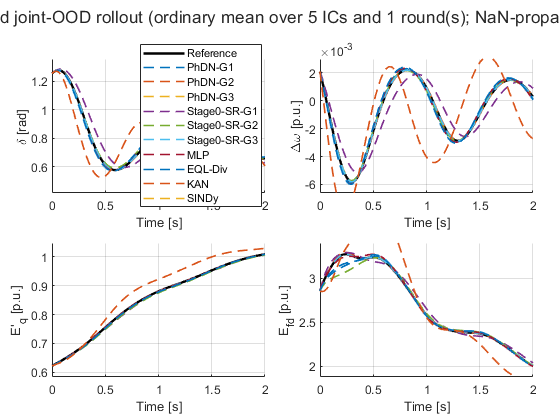

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=500 | Nval=500 | Ntest=1000 | round=1


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test/OOD pools


Sobol scramble=MatousekAffineOwen | skip=1024 | seeds train/val/test/OOD=7301/7401/7501/8501


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=24


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=500; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


State/output normalization=0; rollout solver=ode4, horizon=2.00 s, dt=0.005 s, output times=401, ICs=5


Rollout IC box: lb=[1.18      -0.015        0.58        2.75], ub=[1.32       0.015         0.7           3], representative=[1.28       0.012        0.62         2.9], seed=9301


Rollout guards: max|x|=[10   1  10  20], max|dx/dt|=1e+04, RHS cap=1604, integration/method wall caps=600.0/180.0 s, abort after 3 consecutive failures


Rollout IC shift: joint delta-Eqp-Efd OOD emphasizing terminal-voltage and y4 dynamics | source=SMIB_salient_linear_AVR_joint_voltage_channel_OOD_IC_box


PhDN y4 prior-level ablation (outer coefficients are data-regression initializations):


  PhDN-G1 | 70-10*x4-43*sqrt(square(x3)+square(x1))
  PhDN-G2 | 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))
  PhDN-G3 | 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


SINDy matched prior source: PhDN-G3 only.



RECORDED METHOD REPLAY: PhDN-G1 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00500\method_results\phdn_g1.mat
Replay load: 5.304 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.853038e-06
  true-operator PhDN Test MSE = 6.914970e-07, RMSE = 8.315630e-04
  OOD true-operator PhDN Test MSE = 1.098491e-03, RMSE = 3.314349e-02
  active terms             : 161
  inv / exp / sqrt / cross : 0 / 0 / 0 / 45
  identity-canc

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Validation MSE/RMSE            : 6.759956e-03 / 8.221895e-02
In-distribution test MSE/RMSE  : 3.181336e-03 / 5.640333e-02
OOD test MSE/RMSE              : 5.561749e-01 / 7.457713e-01
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1159.370 s
Native PySR search time        : 1158.465 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: PhDN-G2 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00500\method_results\phdn_g2.mat
Replay load: 5.667 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 5.049813e-06
  true-operator PhDN Test MSE = 2.067493e-06, RMSE = 1.437878e-03
  OOD true-operator PhDN Test MSE = 1.717702e-03, RMSE = 4.144517e-02
  active terms             : 117
  inv / exp / sqrt / cross : 0 / 0 / 2 / 30
  identity-canc

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.470800e-02 / 1.212765e-01
In-distribution test MSE/RMSE  : 7.017990e-03 / 8.377345e-02
OOD test MSE/RMSE              : 1.310241e+00 / 1.144658e+00
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1145.852 s
Native PySR search time        : 1144.879 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: PhDN-G3 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00500\method_results\phdn_g3.mat
Replay load: 4.833 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 3.120437e-28
  true-operator PhDN Test MSE = 1.993581e-28, RMSE = 1.411942e-14
  OOD true-operator PhDN Test MSE = 4.769848e-28, RMSE = 2.183998e-14
  active terms             : 18
  inv / exp / sqrt / cross : 0 / 0 / 1 / 1
  identity-cancel

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Validation MSE/RMSE            : 8.623771e-09 / 9.286426e-05
In-distribution test MSE/RMSE  : 6.374625e-09 / 7.984125e-05
OOD test MSE/RMSE              : 5.363514e-08 / 2.315926e-04
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1162.364 s
Native PySR search time        : 1161.478 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: MLP (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00500\method_results\mlp.mat
Replay load: 0.141 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 3 affine layers (2 hidden layers)
Selected hidden layers       : [64  64]
Selected activation          : silu
Selected parameter count     : 4740
Complete sweep wall time     


RECORDED METHOD REPLAY: EQL-Div (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00500\method_results\eql.mat
Replay load: 0.211 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline raw data split
Method                       : EQL-official-Theano-sweep
Protocol                     : official_eql_div_theano_external_validation_mse
Selected paper depth L       : 3
Official hidden layers L-1   : 2
Selected sparsity lambda     : 1.000e-05
Selected model training N    : 500
Selected active unit


RECORDED METHOD REPLAY: KAN (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00500\method_results\kan.mat
Replay load: 0.115 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline data split
Method                       : Official pyKAN SI accuracy-first sweep with grid inheritance
Selected depth/width         : 2 / 8
Selected sparsification lambda: 0.000e+00
Selected validation-best grid: 5
Selected structure source    : warm_start_accuracy_unpruned
Final selected shape         : [4 8 4]
Act


RECORDED METHOD REPLAY: SINDy (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_00500\method_results\sindy.mat
Replay load: 0.131 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Dictionary source                       : independent SINDy general dictionary: polynomialTerms=1, polyOrder=2, unary={sqrt,exp,sin,cos,log}, unaryOnMonomials=1, operatorCross=1 + union(Stage0SRInitialGuesses: requested=2, added=2, duplicate=0)
Training wall time                      : 0.988 s
Library rows total / used               : 147 / 147
Selected STLSQ th

[rollout predictor] PhDN-G1 | 0.000505405 s/RHS | Compiled fixed PhDN inference: 80 active term columns, 0 fallback terms, no Jacobian/dictionary reconstruction during rollout (compile 0.033 s).

[ODE4 rollout] method=PhDN-G1 | ICs=5 | T=2 s | dt=0.005 s
[ODE4 rollout] PhDN-G1 IC 1/5 start | x0=[1.28 0.012  0.62   2.9]
[ODE4 rollout] PhDN-G1 IC 1 success | elapsed=0.491 s | RMSE=8.526e-03
[ODE4 rollout] PhDN-G1 IC 2/5 start | x0=[1.2118 -0.0079808    0.62577     2.8699]
[ODE4 rollout] PhDN-G1 IC 2 success | elapsed=0.480 s | RMSE=3.238e-04
[ODE4 rollout] PhDN-G1 IC 3/5 start | x0=[1.2799 0.0012611   0.58515    2.7784]
[ODE4 rollout] PhDN-G1 IC 3 success | elapsed=0.519 s | RMSE=1.190e-03
[ODE4 rollout] PhDN-G1 IC 4/5 start | x0=[1.2155 -0.0030692    0.59786     2.7898]
[ODE4 rollout] PhDN-G1 IC 4 success | elapsed=0.489 s | RMSE=7.144e-04
[ODE4 rollout] PhDN-G1 IC 5/5 start | x0=[1.2846 0.0082243   0.68287    2.9475]
[ODE4 rollout] PhDN-G1 IC 5 success | elapsed=0.473 s | RMSE=2.302e-0

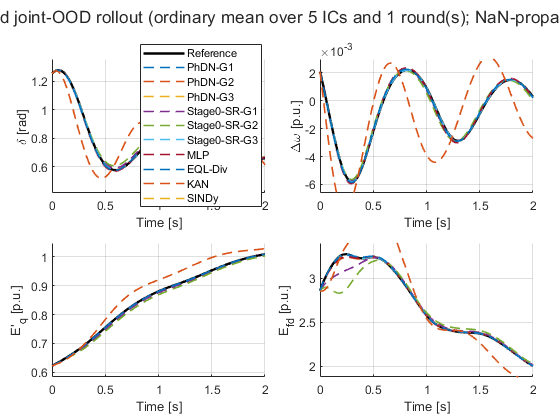

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | Nval=500 | Ntest=1000 | round=1


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test/OOD pools


Sobol scramble=MatousekAffineOwen | skip=1024 | seeds train/val/test/OOD=7301/7401/7501/8501


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=24


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


State/output normalization=0; rollout solver=ode4, horizon=2.00 s, dt=0.005 s, output times=401, ICs=5


Rollout IC box: lb=[1.18      -0.015        0.58        2.75], ub=[1.32       0.015         0.7           3], representative=[1.28       0.012        0.62         2.9], seed=9301


Rollout guards: max|x|=[10   1  10  20], max|dx/dt|=1e+04, RHS cap=1604, integration/method wall caps=600.0/180.0 s, abort after 3 consecutive failures


Rollout IC shift: joint delta-Eqp-Efd OOD emphasizing terminal-voltage and y4 dynamics | source=SMIB_salient_linear_AVR_joint_voltage_channel_OOD_IC_box


PhDN y4 prior-level ablation (outer coefficients are data-regression initializations):


  PhDN-G1 | 70-10*x4-43*sqrt(square(x3)+square(x1))
  PhDN-G2 | 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))
  PhDN-G3 | 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


SINDy matched prior source: PhDN-G3 only.



RECORDED METHOD REPLAY: PhDN-G1 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_01000\method_results\phdn_g1.mat
Replay load: 5.197 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.860547e-05
  true-operator PhDN Test MSE = 6.514081e-06, RMSE = 2.552270e-03
  OOD true-operator PhDN Test MSE = 1.160936e-01, RMSE = 3.407252e-01
  active terms             : 136
  inv / exp / sqrt / cross : 0 / 0 / 0 / 48
  identity-canc

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Validation MSE/RMSE            : 1.454125e-03 / 3.813299e-02
In-distribution test MSE/RMSE  : 6.544603e-04 / 2.558242e-02
OOD test MSE/RMSE              : 1.824177e-02 / 1.350621e-01
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1417.810 s
Native PySR search time        : 1416.768 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: PhDN-G2 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_01000\method_results\phdn_g2.mat
Replay load: 5.900 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 2.367657e-07
  true-operator PhDN Test MSE = 8.766517e-08, RMSE = 2.960831e-04
  OOD true-operator PhDN Test MSE = 1.318938e-04, RMSE = 1.148450e-02
  active terms             : 112
  inv / exp / sqrt / cross : 0 / 0 / 0 / 26
  identity-canc

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 3.540986e-02 / 1.881751e-01
In-distribution test MSE/RMSE  : 1.883855e-02 / 1.372536e-01
OOD test MSE/RMSE              : 4.228880e-01 / 6.502984e-01
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1367.810 s
Native PySR search time        : 1366.783 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: PhDN-G3 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_01000\method_results\phdn_g3.mat
Replay load: 5.316 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 5.728265e-29
  true-operator PhDN Test MSE = 5.555975e-29, RMSE = 7.453842e-15
  OOD true-operator PhDN Test MSE = 3.191262e-29, RMSE = 5.649126e-15
  active terms             : 18
  inv / exp / sqrt / cross : 0 / 0 / 1 / 1
  identity-cancel

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Validation MSE/RMSE            : 3.049359e-09 / 5.522100e-05
In-distribution test MSE/RMSE  : 2.223266e-09 / 4.715153e-05
OOD test MSE/RMSE              : 1.471740e-08 / 1.213153e-04
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1454.289 s
Native PySR search time        : 1453.173 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: MLP (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_01000\method_results\mlp.mat
Replay load: 0.137 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 3 affine layers (2 hidden layers)
Selected hidden layers       : [64  64]
Selected activation          : silu
Selected parameter count     : 4740
Complete sweep wall time     


RECORDED METHOD REPLAY: EQL-Div (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_01000\method_results\eql.mat
Replay load: 0.262 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline raw data split
Method                       : EQL-official-Theano-sweep
Protocol                     : official_eql_div_theano_external_validation_mse
Selected paper depth L       : 3
Official hidden layers L-1   : 2
Selected sparsity lambda     : 1.000e-05
Selected model training N    : 1000
Selected active uni


RECORDED METHOD REPLAY: KAN (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_01000\method_results\kan.mat
Replay load: 0.158 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline data split
Method                       : Official pyKAN SI accuracy-first sweep with grid inheritance
Selected depth/width         : 2 / 8
Selected sparsification lambda: 0.000e+00
Selected validation-best grid: 5
Selected structure source    : warm_start_accuracy_unpruned
Final selected shape         : [4 8 4]
Act


RECORDED METHOD REPLAY: SINDy (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_01000\method_results\sindy.mat
Replay load: 0.140 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Dictionary source                       : independent SINDy general dictionary: polynomialTerms=1, polyOrder=2, unary={sqrt,exp,sin,cos,log}, unaryOnMonomials=1, operatorCross=1 + union(Stage0SRInitialGuesses: requested=2, added=2, duplicate=0)
Training wall time                      : 1.617 s
Library rows total / used               : 147 / 147
Selected STLSQ th

[rollout predictor] PhDN-G1 | 0.000291905 s/RHS | Compiled fixed PhDN inference: 74 active term columns, 0 fallback terms, no Jacobian/dictionary reconstruction during rollout (compile 0.062 s).

[ODE4 rollout] method=PhDN-G1 | ICs=5 | T=2 s | dt=0.005 s
[ODE4 rollout] PhDN-G1 IC 1/5 start | x0=[1.28 0.012  0.62   2.9]
[ODE4 rollout] PhDN-G1 IC 1 success | elapsed=0.504 s | RMSE=2.896e-02
[ODE4 rollout] PhDN-G1 IC 2/5 start | x0=[1.2118 -0.0079808    0.62577     2.8699]
[ODE4 rollout] PhDN-G1 IC 2 success | elapsed=0.465 s | RMSE=1.183e-03
[ODE4 rollout] PhDN-G1 IC 3/5 start | x0=[1.2799 0.0012611   0.58515    2.7784]
[ODE4 rollout] PhDN-G1 IC 3 success | elapsed=0.476 s | RMSE=8.761e-03
[ODE4 rollout] PhDN-G1 IC 4/5 start | x0=[1.2155 -0.0030692    0.59786     2.7898]
[ODE4 rollout] PhDN-G1 IC 4 success | elapsed=0.500 s | RMSE=2.600e-03
[ODE4 rollout] PhDN-G1 IC 5/5 start | x0=[1.2846 0.0082243   0.68287    2.9475]
[ODE4 rollout] PhDN-G1 IC 5 success | elapsed=0.472 s | RMSE=1.295e-0

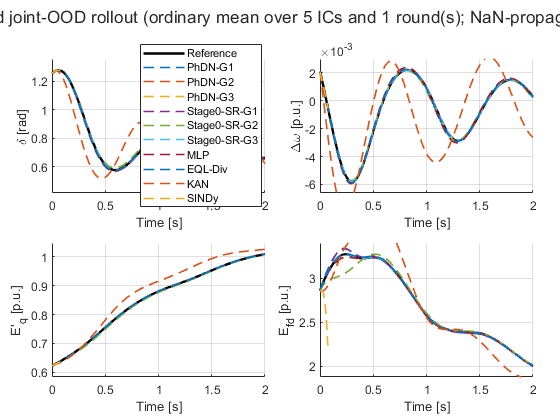

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=2000 | Nval=500 | Ntest=1000 | round=1


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test/OOD pools


Sobol scramble=MatousekAffineOwen | skip=1024 | seeds train/val/test/OOD=7301/7401/7501/8501


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=24


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=2000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


State/output normalization=0; rollout solver=ode4, horizon=2.00 s, dt=0.005 s, output times=401, ICs=5


Rollout IC box: lb=[1.18      -0.015        0.58        2.75], ub=[1.32       0.015         0.7           3], representative=[1.28       0.012        0.62         2.9], seed=9301


Rollout guards: max|x|=[10   1  10  20], max|dx/dt|=1e+04, RHS cap=1604, integration/method wall caps=600.0/180.0 s, abort after 3 consecutive failures


Rollout IC shift: joint delta-Eqp-Efd OOD emphasizing terminal-voltage and y4 dynamics | source=SMIB_salient_linear_AVR_joint_voltage_channel_OOD_IC_box


PhDN y4 prior-level ablation (outer coefficients are data-regression initializations):


  PhDN-G1 | 70-10*x4-43*sqrt(square(x3)+square(x1))
  PhDN-G2 | 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))
  PhDN-G3 | 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


SINDy matched prior source: PhDN-G3 only.



RECORDED METHOD REPLAY: PhDN-G1 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_02000\method_results\phdn_g1.mat
Replay load: 3.097 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.149097e-06
  true-operator PhDN Test MSE = 3.960977e-07, RMSE = 6.293630e-04
  OOD true-operator PhDN Test MSE = 6.661835e-03, RMSE = 8.162007e-02
  active terms             : 283
  inv / exp / sqrt / cross : 0 / 0 / 0 / 112
  identity-can

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Validation MSE/RMSE            : 3.304176e-03 / 5.748197e-02
In-distribution test MSE/RMSE  : 1.573538e-03 / 3.966784e-02
OOD test MSE/RMSE              : 2.003435e-01 / 4.475975e-01
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 815.340 s
Native PySR search time        : 814.081 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: PhDN-G2 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_02000\method_results\phdn_g2.mat
Replay load: 4.169 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.564217e-06
  true-operator PhDN Test MSE = 5.923285e-07, RMSE = 7.696288e-04
  OOD true-operator PhDN Test MSE = 3.536264e-03, RMSE = 5.946649e-02
  active terms             : 95
  inv / exp / sqrt / cross : 0 / 0 / 2 / 24
  identity-cance

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : completed | flagged=1 | extra restarts=2
Validation MSE/RMSE            : 2.086849e-02 / 1.444593e-01
In-distribution test MSE/RMSE  : 9.914059e-03 / 9.956937e-02
OOD test MSE/RMSE              : 8.353057e-01 / 9.139506e-01
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1250.939 s
Native PySR search time        : 1249.702 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: PhDN-G3 (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_02000\method_results\phdn_g3.mat
Replay load: 3.058 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.383343e-22
  true-operator PhDN Test MSE = 8.082856e-23, RMSE = 8.990471e-12
  OOD true-operator PhDN Test MSE = 2.913188e-22, RMSE = 1.706806e-11
  active terms             : 18
  inv / exp / sqrt / cross : 0 / 0 / 1 / 1
  identity-cancel

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Validation MSE/RMSE            : 9.444623e-09 / 9.718345e-05
In-distribution test MSE/RMSE  : 6.753977e-09 / 8.218258e-05
OOD test MSE/RMSE              : 3.097340e-09 / 5.565375e-05
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 826.656 s
Native PySR search time        : 825.316 s
No additional baseline cost    : yes



RECORDED METHOD REPLAY: MLP (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_02000\method_results\mlp.mat
Replay load: 0.061 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 3 affine layers (2 hidden layers)
Selected hidden layers       : [64  64]
Selected activation          : silu
Selected parameter count     : 4740
Complete sweep wall time     


RECORDED METHOD REPLAY: EQL-Div (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_02000\method_results\eql.mat
Replay load: 0.137 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline raw data split
Method                       : EQL-official-Theano-sweep
Protocol                     : official_eql_div_theano_external_validation_mse
Selected paper depth L       : 3
Official hidden layers L-1   : 2
Selected sparsity lambda     : 1.000e-05
Selected model training N    : 2000
Selected active uni


RECORDED METHOD REPLAY: KAN (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_02000\method_results\kan.mat
Replay load: 0.074 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Data source                  : Exact PhDN/baseline data split
Method                       : Official pyKAN SI accuracy-first sweep with grid inheritance
Selected depth/width         : 2 / 8
Selected sparsification lambda: 0.000e+00
Selected validation-best grid: 5
Selected structure source    : warm_start_accuracy_unpruned
Final selected shape         : [4 8 4]
Act


RECORDED METHOD REPLAY: SINDy (training skipped)
Source: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR\round_01\N_02000\method_results\sindy.mat
Replay load: 0.081 s | mode=direct_independent_method
Report mode: exact_saved_report | compact=1
[minimal replay report: historical sweep/candidate/term details omitted]
[full archived report remains unchanged in recordedConsoleReport]
Dictionary source                       : independent SINDy general dictionary: polynomialTerms=1, polyOrder=2, unary={sqrt,exp,sin,cos,log}, unaryOnMonomials=1, operatorCross=1 + union(Stage0SRInitialGuesses: requested=2, added=2, duplicate=0)
Training wall time                      : 1.959 s
Library rows total / used               : 147 / 147
Selected STLSQ th

[rollout predictor] PhDN-G1 | 0.00052207 s/RHS | Compiled fixed PhDN inference: 145 active term columns, 0 fallback terms, no Jacobian/dictionary reconstruction during rollout (compile 0.081 s).

[ODE4 rollout] method=PhDN-G1 | ICs=5 | T=2 s | dt=0.005 s
[ODE4 rollout] PhDN-G1 IC 1/5 start | x0=[1.28 0.012  0.62   2.9]
[ODE4 rollout] PhDN-G1 IC 1 success | elapsed=0.912 s | RMSE=6.399e-02
[ODE4 rollout] PhDN-G1 IC 2/5 start | x0=[1.2118 -0.0079808    0.62577     2.8699]
[ODE4 rollout] PhDN-G1 IC 2 success | elapsed=0.862 s | RMSE=8.438e-05
[ODE4 rollout] PhDN-G1 IC 3/5 start | x0=[1.2799 0.0012611   0.58515    2.7784]
[ODE4 rollout] PhDN-G1 IC 3 success | elapsed=0.964 s | RMSE=1.745e-03
[ODE4 rollout] PhDN-G1 IC 4/5 start | x0=[1.2155 -0.0030692    0.59786     2.7898]
[ODE4 rollout] PhDN-G1 IC 4 success | elapsed=0.868 s | RMSE=2.078e-04
[ODE4 rollout] PhDN-G1 IC 5/5 start | x0=[1.2846 0.0082243   0.68287    2.9475]
[ODE4 rollout] PhDN-G1 IC 5 success | elapsed=0.865 s | RMSE=7.004e-0

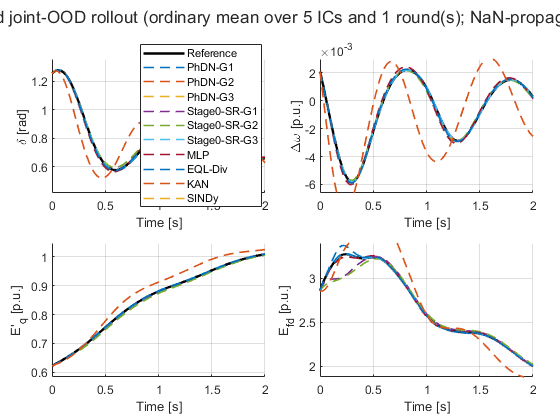


%% Stage 0: trivial-output bypass plus native multi-output PySR
% The case-local canonical x1,...,x4 map now makes the PySR text path safe.
% Retain bypass only for equations reproduced essentially at machine zero.
% With the threshold below, the trivial delta_dot equation may bypass, while
% the salient-pole swing equation, flux equation, and nested terminal-voltage
% magnitude equation are forced through native PySR. This keeps Stage0-SR close to a
% genuine SR baseline instead of allowing a rich flat dictionary to replace
% cos(delta) by a dense local surrogate.
Stage0SingleLayerBypassEnable = true;
Stage0SingleLayerBypassThreshold = 1e-24;

% Fixed SINDy-bypass dictionary only; this is separate from the editable
% native-PySR grammar port defined below.
Stage0BasePolyOrder = 2;
Stage0BaseUnaryOperators = {'inv','sqrt','exp','sin','cos','log'};
Stage0BaseIncludeUnaryOnMonomials = true;
Stage0BaseIncludeOperatorCrossTerms = true;
Stage0BaseIncludeSinCosPair = false;
Stage0BaseMaxLibraryTerms = Inf;
Stage0STLSQThresholdList = [0,1e-8,1e-7,1e-6,1e-5,1e-4,1e-3];
Stage0STLSQMaxIter = 10;
Stage0RidgeLambda = 0;
Stage0WorstOutputWeight = 0.10;

Stage0PythonExe = 'C:\Users\hhy\miniconda3\envs\pysr_sr\python.exe';
Stage0PySRPaperRoot = fullfile(projectRoot,'baselines','pysr_paper_main');
Stage0WorkRoot = fullfile(projectRoot,'tmp','stage0_pysr_single_generator_runs');
Stage0GrammarCasemode = casemode;

% User-editable native-PySR grammar port for this system-identification demo.
% The recommended grammar uses only fine-grained arithmetic, square/square-root,
% and fixed rotor-angle trigonometric atoms.
Stage0UseCustomSRGrammar = true;
% Shared typed physical grammar for all four output dimensions.
% State-dependent division is removed; fixed machine/network denominators are
% absorbed into fitted scalar coefficients.
Stage0SRBinaryOperators = {'+','-','*'};
Stage0SRUnaryOperators = {'square','sqrt','sin','cos'};
Stage0TypedPhysicalPriorEnable = true;
Stage0TypedPhysicalPriorMode = 'single_generator_dynamic';
Stage0SRTrigAllowedVariables = {'x1'};
Stage0SRForbidStateDependentDivision = true;
Stage0SROperatorComplexities = struct();
% SR receives sin(x1) and cos(x1) as fixed derived inputs. Recursive sin/cos
% are removed, so shifted, scaled, polynomial, and nested phases cannot occur.
Stage0SRStrictTrigAtomsOnly = false;
Stage0SRForbidNestedTrig = true;
Stage0SRForbidNestedSquare = true;
Stage0SRForbidNestedSqrt = true;
% PySR 2.0 shared initial-equation library.  Three independent PhDN variants
% are defined below.  They share the same grammar, data, random states, reusable
% y2 bases, and optimization settings; only the y4 structural-prior level varies.
% The outer coefficients shown here are data-regression initializations rather
% than ground-truth parameters.  Official fraction_replaced_guesses periodically
% re-injects the corresponding library into every unresolved output.
% This remains a soft prior: descendants and substructures are not protected.
Stage0SRMinimumPySRVersion = '2.0.0a2';
Stage0SRRequirePySR2 = true;
Stage0SRInitialGuessesEnable = true;
Stage0SRInitialGuessFraction = 0.10;
Stage0SRInitialGuessSingleBases = {};

% G1: coarse Euclidean-magnitude prior.
Stage0SRInitialGuessSparseCombinations_G1 = { ...
    '1.1e-1-1.5e-1*sin(2*x1)',...
    '70-10*x4-43*sqrt(square(x3)+square(x1))'};

% G2: correct trigonometric branch type but no x3--cos(x1) coupling.
Stage0SRInitialGuessSparseCombinations_G2 = { ...
    '5.0e-1-2.0e-2*x3*sin(x1)+6.8e-1*sin(2*x1)',...
    '76-10*x4-49*sqrt(square(x3)+square(sin(x1)))'};

% G3: strongest prior; correct coupled magnitude topology with unit internal
% ratios.  Internal ratios and all final coefficients remain learnable.
Stage0SRInitialGuessSparseCombinations_G3 = { ...
    '5.0e-1-2.0e-2*x3*sin(x1)+6.8e-1*sin(2*x1)',...
    '100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))'};

Stage0SRInitialGuesses_G1 = [Stage0SRInitialGuessSingleBases, ...
    Stage0SRInitialGuessSparseCombinations_G1];
Stage0SRInitialGuesses_G2 = [Stage0SRInitialGuessSingleBases, ...
    Stage0SRInitialGuessSparseCombinations_G2];
Stage0SRInitialGuesses_G3 = [Stage0SRInitialGuessSingleBases, ...
    Stage0SRInitialGuessSparseCombinations_G3];

% Backward-compatible alias and the unique SINDy matched-prior source.
Stage0SRInitialGuesses = Stage0SRInitialGuesses_G3;
% Example broader fallback grammar:
% Stage0SRUnaryOperators = {'square','cube','inv','sqrt','exp','sin','cos','log'};
% Stage0SROperatorComplexities.cube = 3;
% Stage0SROperatorComplexities.exp = 5;
% Stage0SROperatorComplexities.log = 5;

Stage0PopulationSize = 100;
Stage0InnerNumRestarts = 3;
Stage0InnerNIterations = 700;
Stage0InnerPopulations = 24;
Stage0PopulationBudgetMode = 'fixed_total';
Stage0InnerRandomStateStride = 100;

% General output-self-referenced Stage-0 targeted rescue.
% Trigger A: best normalized validation MSE remains above the soft threshold
% AND the ordinary restarts are unstable for that same output.
% Trigger B: the ordinary restarts are relatively consistent, but even their
% best normalized validation MSE remains above the hard threshold.
% A/B both add one official single-output PySR restart. A second rescue restart
% is allowed only if the first reduces the running best q by at least 50% and
% the soft threshold is still not reached. Known derivative-label noise raises
% the soft/hard thresholds above 4x the expected validation-noise MSE floor.
Stage0AdaptiveRescueEnable = true;
Stage0AdaptiveRescueSoftNormalizedMSE = 1e-6;
Stage0AdaptiveRescueHardNormalizedMSE = 1e-4;
Stage0AdaptiveRescueInstabilityFactor = 5;
Stage0AdaptiveRescueContinueImprovementRatio = 0.5;
Stage0AdaptiveRescueUseKnownNoiseFloor = true;
Stage0AdaptiveRescueNoiseFloorMultiplier = 4;
Stage0AdaptiveRescueMaxRestartsPerOutput = 2;
Stage0AdaptiveRescuePopulationMultiplier = 1.5;
Stage0AdaptiveRescueMinPopulations = 8;
Stage0AdaptiveRescueMaxPopulations = 20;
Stage0AdaptiveRescueExplicitPopulations = []; % [] -> adaptive population rule
Stage0AdaptiveRescueNIterations = Stage0InnerNIterations;
Stage0AdaptiveRescueMaxOutputs = 3;
Stage0AdaptiveRescueUseOutputSpecificInitialGuess = true;
Stage0AdaptiveRescueSeedOffset = 10000;
Stage0AdaptiveRescueOutputSeedStride = 1000;
Stage0AdaptiveRescueRestartSeedStride = 100;

% Official PySR growth-biased evolution profile. No candidate receives a custom
% loss or lineage bonus. Instead, user guesses and random individuals remain
% under the same data-loss competition while mutations favor structure-preserving
% outward growth. add_node appends/prepends around the complete tree; insert_node
% wraps a selected existing subtree without changing that subtree internally.
% Direct operator/feature replacement, tree rotation, randomization, deletion,
% and simplification are suppressed. Constants may still mutate or be optimized.
Stage0TournamentSelectionN = 8;
Stage0TournamentSelectionP = 0.85;

% use default settings
Stage0CrossoverProbability = [];

Stage0WeightAddNode        = [];
Stage0WeightInsertNode     = [];
Stage0WeightDeleteNode     = [];
Stage0WeightDoNothing      = [];
Stage0WeightMutateConstant = [];
Stage0WeightMutateOperator = [];
Stage0WeightMutateFeature  = [];
Stage0WeightSwapOperands   = [];
Stage0WeightRotateTree     = [];
Stage0WeightRandomize      = [];
Stage0WeightSimplify       = [];
Stage0WeightOptimize       = [];

Stage0OptimizeProbability = [];
Stage0ShouldSimplify      = [];
% ncycles_per_iteration remains unspecified. Population size, restart count,
% iteration budget, batching, grammar, guesses, and Stage-1/2 remain unchanged.
% Official crossover cannot be restricted to the root, so it is retained only
% at a low probability for occasional combination of independently grown trees.
Stage0MaxDepth = 10;
Stage0MaxSize = 30;
Stage0Parsimony = 1e-6;
Stage0ModelSelection = 'best';
Stage0RandomState = 1;
Stage0Deterministic = false;
Stage0Parallelism = 'multithreading';
% System-identification-only PySR mini-batch evolution. Keep at least 250
% samples per batch and preserve a 25% batch fraction once Ntrain exceeds 1000.
% For TrainingSampleList=[250,500,1000,2000], this gives [250,250,250,500].
Stage0Batching = false;
Stage0BatchSizeList = TrainingSampleList;
assert(numel(Stage0BatchSizeList)==numel(TrainingSampleList), ...
    'Stage0BatchSizeList must match TrainingSampleList.');
assert(all(Stage0BatchSizeList>=1 & Stage0BatchSizeList<=TrainingSampleList), ...
    ['Every Stage-0 batch size must be a positive integer no larger than ', ...
     'its corresponding training-sample count.']);
Stage0StrictDeterministicTestMode = false;
Stage0RepeatabilityPredictionTolerance = 1e-12;
% All-output, scale-aware machine-precision training early stop.  PySR advances
% in warm-start chunks and stops a restart only after every unresolved output
% reaches the full-training Hall-of-Fame MSE threshold. Remaining restarts are
% skipped only after the fixed external validation set confirms the same floor.
Stage0MachinePrecisionEarlyStopEnable = true;
Stage0MachinePrecisionEarlyStopAbsMSE = 1e-12;
Stage0MachinePrecisionEarlyStopRelMSE = 1e-12;
Stage0MachinePrecisionEarlyStopCheckInterval = 50;
Stage0MachinePrecisionEarlyStopMinIterations = 50;
Stage0MachinePrecisionEarlyStopAcrossRestarts = true;
Stage0Verbosity = 1;
Stage0Progress = false;
Stage0TopKExpressionsToReport = 10;
Stage0DisplayCandidateRankings = true;
Stage0CandidateRankingTopK = 10;
Stage0SemanticDedupTolerance = 1e-8;
Stage0StructureScoreEnable = true;
Stage0StructureValidationMultiplier = 4.0;
Stage0StructureValidationWeight = 0.30;
% Below this scale-aware validation-MSE floor, numerical differences are
% treated as ties and the simpler structure is selected.
Stage0StructureMachineErrorAbsMSEFloor = 1e-12;
Stage0StructureMachineErrorRelMSEFloor = 1e-12;
Stage0StructureFrontierMaxAbs = 20;
Stage0StructureNeighborhoodMaxDistance = 0.55;
Stage0StructureNeighborhoodMinDistance = 0.10;
Stage0StructureNeighborhoodComplexityWindow = 8;

%% Stage 1 and Stage 2
Stage1EnableAugmentation = true;
Stage1AugmentationPolyOrder = Stage0BasePolyOrder;
Stage1AugmentationIncludeCrossTerms = true;
Stage1ForceStage0SeedOnly = true;
Stage1ExpandBoundsToIncludeStage0Seed = true;
Stage1Stage0SeedBoundMargin = 1e-6;
Stage1RequireExactStage0Reproduction = true;
Stage1Stage0ReproductionRelTolerance = 1e-6;
Stage1Stage0ReproductionAbsTolerance = 1e-10;

Stage2Enable = true;
FinalLSQMaxIter = 500;
FinalLSQMaxFunEvals = 5e4;
FinalLSQMaxRelValIncrease = 1e-10;
PostBPPruneEnable = true;
PostBPPruneNumIterations = 1;
PostBPPruneAbsThreshold = 1e-4;
PostBPPruneRelThreshold = 0;
PostBPPruneMaxRelValIncrease = 1e-4;

%% Dynamic rollout simulation controls
% Fixed-step classical fourth-order Runge--Kutta (ODE4/RK4).
RolloutSolver = 'ode4';
RolloutHorizon = 2.0;                  % seconds
RolloutFixedStep = 0.005;              % seconds; 400 RK4 steps over 2 s
RolloutNOutputTimes = round(RolloutHorizon/RolloutFixedStep)+1;
RolloutNInitialConditions = 5;   % debug with one fixed IC first

% Mild y4-focused OOD initial-condition box. Delta and Eqp are only slightly
% outside/near the ID boundary, while Efd is just above its ID upper bound.
% Start with one fixed IC to determine whether prior failures were caused by
% excessive OOD severity rather than by the rollout implementation.
% State order: [delta, domega, Eqp, Efd].
RolloutInitialConditionLowerBound = [1.18,-0.015,0.58,2.75];
RolloutInitialConditionUpperBound = [1.32, 0.015,0.70,3.00];
RolloutReferenceInitialCondition = [1.28,0.012,0.62,2.90];
RolloutInitialConditionSeed = 9301;

% Fail-fast guards. A pathological learned vector field is reported as a
% failed rollout instead of consuming an unbounded amount of time.
RolloutMaxStateAbs = [10,1,10,20];
RolloutMaxDerivativeAbs = 1e4;
RolloutMaxRhsEvaluationsPerIntegration = ...
    4*(RolloutNOutputTimes-1)+4;
RolloutMaxWallTimePerIntegration = 600; % seconds
RolloutMaxWallTimePerMethod = 180;     % seconds
RolloutAbortAfterConsecutiveFailures = 3;
RolloutProgressEveryIC = 1;
RolloutFailureMetricValue = Inf;

%% Methods and output controls
InitializationMode = 'skip';
EnableOOD = true;                % hard joint vector-field OOD + y4-focused rollout
DisplayDictionary = true;
PrintFinalXiMatrices = false;
FinalXiPrintPrecision = 4;
FinalXiPrintOnlyActive = false;
SaveResults = false;
ResultsFile = fullfile(OutputSummaryDir,'single_generator_dynamic_results.mat');

% -------------------------------------------------------------------------
% Method switches: true always means train the method in the current N/round.
% PhDN-G1/G2/G3 are three independent methods. Enabling all three approximately
% triples the PySR Stage-0 cost relative to one PhDN run.
% -------------------------------------------------------------------------
RunPhDNMainModel_G1 = false;
RunPhDNMainModel_G2 = false;
RunPhDNMainModel_G3 = false;
RunMLPBaseline = false;
RunEQLBaseline = false;
RunKANBaseline = false;
RunSINDyBaseline = false;
IncludeStage0SRAblationsInComparison = false;

% -------------------------------------------------------------------------
% Recorded-method replay controls.
% Run*=true always trains and takes priority. Only when Run*=false and the
% corresponding displayRecordReport_*=true is the saved method for the current
% N/round loaded, replayed, and included in rollout/tables/figures.
% -------------------------------------------------------------------------
RecordedBaselineSourceRoot = OutputCaseRoot;
RecordedBaselineReplayStrict = false; % backup replay: allow archived configuration mismatch
% Minimal recorded-report mode for replay-only MLX runs. When true, every
% method prints only final architecture/complexity, key ID/OOD metrics, and
% timing needed for scientific comparison. Historical sweep/candidate/term
% tables are omitted; saved result structures remain unchanged.
RecordedReportCompactMode = true;
displayRecordReport_PhDN_G1 = true;
displayRecordReport_PhDN_G2 = true;
displayRecordReport_PhDN_G3 = true;
displayRecordReport_SR1 = true;
displayRecordReport_SR2 = true;
displayRecordReport_SR3 = true;
displayRecordReport_MLP = true;
displayRecordReport_EQL = true;
displayRecordReport_KAN = true;
displayRecordReport_SINDy = true;

% -------------------------------------------------------------------------
% MLP case-local sweep controls
% Feynman-style depth/activation sweep, with 64 neurons in every hidden layer.
% Depth is the number of affine layers, so depth D has D-1 hidden layers.
% -------------------------------------------------------------------------
MLPSeed = 1;                       % shared round seed for MLP/KAN/EQL
MLPProtocol = 'kan_feynman_sweep';
MLPWidth = 64;
MLPDepthList = 2:6;
MLPActivationList = {'tanh','relu','silu'};
MLPOptimizer = 'LBFGS';
MLPSteps = 500;
MLPLearningRate = 1.0;
MLPDtype = 'float64';
MLPDevice = 'cpu';
MLPTorchNumThreads = 0;
MLPNormalizeInputs = true;
MLPNormalizeOutputs = true;
MLPPythonExe = Stage0PythonExe;
MLPPyKANRoot = fullfile(projectRoot,'third_party','pykan');
MLPWorkRoot = fullfile(projectRoot,'tmp','mlp_single_generator_runs');
MLPDepthEarlyStop = true;
MLPDepthEarlyStopPatience = 1;
MLPDepthEarlyStopRelativeTolerance = 0.0;
MLPDisplaySweepTable = true;
MLPVerbose = true;

% -------------------------------------------------------------------------
% KAN case-local sweep controls
% -------------------------------------------------------------------------
KANPythonExe = Stage0PythonExe;
PyKANRoot = fullfile(projectRoot,'third_party','pykan');
KANWidth = 8;
KANDepthList = 2:6;
KANGridList = [3,5,10,20,50,100,200];
KANSplineOrder = 3;
% Accuracy-first training uses lambda=0 before any sparsification. These mild
% lambdas are attempted only after an accurate unpruned grid checkpoint exists.
KANSparsificationLambdaList = [1e-5,1e-4,1e-3];
KANStepsPerGrid = 200;
KANAccuracyStepsPerGrid = 200;
KANSparsificationSteps = 200;
KANRecoveryStepsPerGrid = 200;
KANOptimizer = 'LBFGS';
KANLearningRate = 1.0;
KANPruneNodeThreshold = 1e-2;
KANPruneEdgeThreshold = 3e-2;
% Both pruned and unpruned fallback branches complete zero-lambda recovery and
% the remaining grid-refinement schedule before validation comparison.
KANPruneValidationGuardEnable = true;
KANPruneMaxRelativeValidationIncrease = 0.0;
KANGridEarlyStop = true;
KANGridEarlyStopPatience = 2;
KANGridEarlyStopRelativeTolerance = 0.015;
KANDepthEarlyStop = true;
KANDepthEarlyStopPatience = 1; % stop after the next meaningfully worse depth
KANDepthEarlyStopRelativeTolerance = 0.01;
% For nested sample sizes, KAN complexity is defined by spline grid G only.
% A larger sample size starts at least from the previously selected G and also
% receives the previous selected native model as a non-regression/warm candidate.
KANEnforceNondecreasingGridAcrossSamples = true;
KANWarmStartAcrossSamples = true;
KANDtype = 'float64';
KANDevice = 'cpu';
KANTorchNumThreads = 0;
KANNormalizeInputs = true;
KANNormalizeOutputs = true;
KANWorkRoot = fullfile(projectRoot,'tmp','kan_single_generator_runs');
KANDisplaySweepTable = true;
KANVerbose = true;

% -------------------------------------------------------------------------
% EQL-Div case-local sweep controls
% -------------------------------------------------------------------------
EQLPythonExe = 'C:\Users\hhy\miniconda3\envs\eql_official\python.exe';
EQLOfficialRoot = fullfile(projectRoot,'baselines','eql','official_eql');
EQLDepthList = [2,3,4,5];
EQLLambdaList = [1e-5,1e-3];
EQLUnitsPerUnaryType = 10;
EQLMultiplicationUnits = 10;
EQLStepsPerHiddenLayer = 3000;
EQLBatchSize = 20;
EQLLearningRate = 1e-3;
EQLGradient = 'adam';
EQLLambdaL2 = 0;
EQLPenaltyEvery = 50;
EQLValidateEvery = 10;
EQLCandidateWorkers = 0;
EQLOfficialVerbose = false;
EQLNormalizeInputs = true;
EQLNormalizeOutputs = true;
EQLTheanoFlags = 'device=cpu,floatX=float64,optimizer=fast_run,exception_verbosity=high';
EQLWorkRoot = fullfile(projectRoot,'tmp','eql_single_generator_runs');
EQLDepthEarlyStop = true;
EQLDepthEarlyStopPatience = 1;
EQLDepthEarlyStopRelativeTolerance = 0.015;
% Paper protocol: every reported point is a model trained on exactly the
% current N samples. The previous smaller-N model is used only as a fixed-Val
% target and optional initialization for a new current-N official EQL run; it
% is never copied unchanged into the current-N paper curve.
EQLFullDepthScheduleEachSample = true;
EQLCheckpointSelectionMode = 'physical_validation_mse';
EQLUsePreviousModelAsSearchTargetAcrossSamples = true;
EQLWarmStartPreviousModel = true;
EQLWarmStartRestarts = 1;
% If the first current-N sweep does not strictly beat the previous fixed-Val
% reference, rerun the best two L/lambda configurations with up to three new
% independent seeds. Early stopping is overridden while the target is pending.
EQLAdaptiveRescueRestarts = 3;
EQLAdaptiveRescueTopK = 2;
EQLStrictImprovementRelativeMargin = 1e-3; % require at least 0.1% fixed-Val improvement
EQLStrictImprovementAbsoluteMargin = 0.0;
EQLStrictTargetOverridesDepthEarlyStop = true;
EQLDisplaySweepTable = true;
EQLVerbose = true;

% Build the complete option structs using the case-local helper, then apply
% every user-facing control above explicitly. The helper is not the hidden
% source of these settings; it only supplies unchanged shared/default fields.
baselineSweep = single_generator_dynamic_baseline_sweep_options( ...
    projectRoot,Stage0PythonExe);
baselineSweep.runMLP = RunMLPBaseline;
baselineSweep.runEQL = RunEQLBaseline;
baselineSweep.runKAN = RunKANBaseline;
baselineSweep.runSINDy = RunSINDyBaseline;

baselineSweep.mlp.protocol = MLPProtocol;
baselineSweep.mlp.width = MLPWidth;
baselineSweep.mlp.depthList = MLPDepthList;
baselineSweep.mlp.activationList = MLPActivationList;
baselineSweep.mlp.optimizer = MLPOptimizer;
baselineSweep.mlp.steps = MLPSteps;
baselineSweep.mlp.learningRate = MLPLearningRate;
baselineSweep.mlp.dtype = MLPDtype;
baselineSweep.mlp.device = MLPDevice;
baselineSweep.mlp.torchNumThreads = MLPTorchNumThreads;
baselineSweep.mlp.normalizeInputs = MLPNormalizeInputs;
baselineSweep.mlp.normalizeOutputs = MLPNormalizeOutputs;
baselineSweep.mlp.pythonExe = MLPPythonExe;
baselineSweep.mlp.pykanRoot = MLPPyKANRoot;
baselineSweep.mlp.workRoot = MLPWorkRoot;
baselineSweep.mlp.depthEarlyStop = MLPDepthEarlyStop;
baselineSweep.mlp.depthEarlyStopPatience = MLPDepthEarlyStopPatience;
baselineSweep.mlp.depthEarlyStopRelativeTolerance = MLPDepthEarlyStopRelativeTolerance;
baselineSweep.mlp.displaySweepTable = MLPDisplaySweepTable;
baselineSweep.mlp.verbose = MLPVerbose;

baselineSweep.kan.pythonExe = KANPythonExe;
baselineSweep.kan.pykanRoot = PyKANRoot;
baselineSweep.kan.width = KANWidth;
baselineSweep.kan.depthList = KANDepthList;
baselineSweep.kan.minimumDepth = min(KANDepthList);
baselineSweep.kan.gridList = KANGridList;
baselineSweep.kan.splineOrder = KANSplineOrder;
baselineSweep.kan.sparsificationLambdaList = KANSparsificationLambdaList;
baselineSweep.kan.stepsPerGrid = KANStepsPerGrid;
baselineSweep.kan.accuracyStepsPerGrid = KANAccuracyStepsPerGrid;
baselineSweep.kan.sparsificationSteps = KANSparsificationSteps;
baselineSweep.kan.recoveryStepsPerGrid = KANRecoveryStepsPerGrid;
baselineSweep.kan.optimizer = KANOptimizer;
baselineSweep.kan.learningRate = KANLearningRate;
baselineSweep.kan.pruneNodeThreshold = KANPruneNodeThreshold;
baselineSweep.kan.pruneEdgeThreshold = KANPruneEdgeThreshold;
baselineSweep.kan.pruneValidationGuardEnable = KANPruneValidationGuardEnable;
baselineSweep.kan.pruneMaxRelativeValidationIncrease = KANPruneMaxRelativeValidationIncrease;
baselineSweep.kan.minimumGrid = min(KANGridList);
baselineSweep.kan.warmStartEnable = KANWarmStartAcrossSamples;
baselineSweep.kan.warmStartCheckpointPath = '';
baselineSweep.kan.warmStartNormalization = struct();
baselineSweep.kan.gridEarlyStop = KANGridEarlyStop;
baselineSweep.kan.gridEarlyStopPatience = KANGridEarlyStopPatience;
baselineSweep.kan.gridEarlyStopRelativeTolerance = KANGridEarlyStopRelativeTolerance;
baselineSweep.kan.depthEarlyStop = KANDepthEarlyStop;
baselineSweep.kan.depthEarlyStopPatience = KANDepthEarlyStopPatience;
baselineSweep.kan.depthEarlyStopRelativeTolerance = KANDepthEarlyStopRelativeTolerance;
baselineSweep.kan.dtype = KANDtype;
baselineSweep.kan.device = KANDevice;
baselineSweep.kan.torchNumThreads = KANTorchNumThreads;
baselineSweep.kan.normalizeInputs = KANNormalizeInputs;
baselineSweep.kan.normalizeOutputs = KANNormalizeOutputs;
baselineSweep.kan.workRoot = KANWorkRoot;
baselineSweep.kan.displaySweepTable = KANDisplaySweepTable;
baselineSweep.kan.verbose = KANVerbose;

baselineSweep.eql.pythonExe = EQLPythonExe;
baselineSweep.eql.officialRoot = EQLOfficialRoot;
baselineSweep.eql.depthList = EQLDepthList;
baselineSweep.eql.minimumDepth = min(EQLDepthList); % compatibility field; adapter enforces full list
baselineSweep.eql.fullDepthScheduleEachSample = EQLFullDepthScheduleEachSample;
baselineSweep.eql.checkpointSelectionMode = EQLCheckpointSelectionMode;
baselineSweep.eql.warmStartPreviousModel = EQLWarmStartPreviousModel;
baselineSweep.eql.warmStartRestarts = EQLWarmStartRestarts;
baselineSweep.eql.adaptiveRescueRestarts = EQLAdaptiveRescueRestarts;
baselineSweep.eql.adaptiveRescueTopK = EQLAdaptiveRescueTopK;
baselineSweep.eql.strictImprovementRelativeMargin = EQLStrictImprovementRelativeMargin;
baselineSweep.eql.strictImprovementAbsoluteMargin = EQLStrictImprovementAbsoluteMargin;
baselineSweep.eql.strictTargetOverridesDepthEarlyStop = EQLStrictTargetOverridesDepthEarlyStop;
baselineSweep.eql.lambdaList = EQLLambdaList;
baselineSweep.eql.unitsPerUnaryType = EQLUnitsPerUnaryType;
baselineSweep.eql.multiplicationUnits = EQLMultiplicationUnits;
baselineSweep.eql.stepsPerHiddenLayer = EQLStepsPerHiddenLayer;
baselineSweep.eql.batchSize = EQLBatchSize;
baselineSweep.eql.learningRate = EQLLearningRate;
baselineSweep.eql.gradient = EQLGradient;
baselineSweep.eql.lambdaL2 = EQLLambdaL2;
baselineSweep.eql.penaltyEvery = EQLPenaltyEvery;
baselineSweep.eql.validateEvery = EQLValidateEvery;
baselineSweep.eql.candidateWorkers = EQLCandidateWorkers;
baselineSweep.eql.officialVerbose = EQLOfficialVerbose;
baselineSweep.eql.normalizeInputs = EQLNormalizeInputs;
baselineSweep.eql.normalizeOutputs = EQLNormalizeOutputs;
baselineSweep.eql.theanoFlags = EQLTheanoFlags;
baselineSweep.eql.workRoot = EQLWorkRoot;
baselineSweep.eql.depthEarlyStop = EQLDepthEarlyStop;
baselineSweep.eql.depthEarlyStopPatience = EQLDepthEarlyStopPatience;
baselineSweep.eql.depthEarlyStopRelativeTolerance = EQLDepthEarlyStopRelativeTolerance;
baselineSweep.eql.displaySweepTable = EQLDisplaySweepTable;
baselineSweep.eql.verbose = EQLVerbose;

SINDyThresholdList = [0,1e-8,3e-8,1e-7,3e-7,1e-6,3e-6,1e-5,3e-5,1e-4,3e-4,1e-3];
SINDyMaxSTLSQIter = 10;
SINDyRidgeLambda = 0;
SINDyDictionaryMode = 'general';
SINDyPolyOrder = 2;
% Apply the same known-state physical rules as Stage-0 SR. No inverse basis is
% generated; sin/cos are restricted to rotor angle v1.
SINDyUnaryOperators = {'sqrt','exp','sin','cos','log'};
SINDyTypedPhysicalPriorEnable = true;
SINDyTrigAllowedVariableIndex = 1;
SINDyForbidStateDependentDivision = true;
SINDyIncludeUnaryOnMonomials = true;
SINDyIncludeOperatorCrossTerms = true;
% Do not add target-output-specific Vq/Vd, complete Vt, voltage-error, or
% sin(2*v1) columns. All outputs share this same one-layer dictionary.
SINDyUsePhdnDictionarySupport = false;
SINDyCenterScaleLibrary = false;
SINDyRemoveNearConstantRows = false;
SINDyVerbose = true;
SINDyMaxTermsToPrint = 40;

%% Run nested sample-efficiency sweep
allResults = struct();
systemIdentificationRows = struct([]);
standardSummaryRows = struct([]);
iStandardSummary = 0;

for iRound = 1:NumRounds
    roundStage0RandomState = Stage0RandomState+(iRound-1)*RoundRandomStateStride;
    roundMlpSeed = MLPSeed+(iRound-1)*RoundRandomStateStride;
    previousEQLResult = [];
    previousKANSelectedGrid = min(KANGridList);
    previousKANCheckpointPath = '';
    previousKANNormalization = struct();

    fprintf('\n############################################################\n');
    fprintf('SingleGeneratorDynamic round %d/%d | PySR state=%d | MLP seed=%d\n', ...
        iRound,NumRounds,roundStage0RandomState,roundMlpSeed);
    fprintf('############################################################\n');
    fprintf('MLP sweep: width=%d, depth=[%s], activations={%s}, depthEarlyStop=%d\n', ...
        baselineSweep.mlp.width,num2str(baselineSweep.mlp.depthList), ...
        strjoin(baselineSweep.mlp.activationList,','),baselineSweep.mlp.depthEarlyStop);
    fprintf(['KAN sweep: width=%d, depth=[%s], sparse lambda=[%s], ', ...
        'grid patience=%d, grid tolerance=%.2f%%, depth lookahead=%d, pruneGuard=%d\n'], ...
        baselineSweep.kan.width,num2str(baselineSweep.kan.depthList), ...
        num2str(baselineSweep.kan.sparsificationLambdaList), ...
        baselineSweep.kan.gridEarlyStopPatience, ...
        100*baselineSweep.kan.gridEarlyStopRelativeTolerance, ...
        baselineSweep.kan.depthEarlyStopPatience,baselineSweep.kan.pruneValidationGuardEnable);
    fprintf('EQL sweep: depth=[%s], lambda=[%s], depthEarlyStop=%d\n', ...
        num2str(baselineSweep.eql.depthList),num2str(baselineSweep.eql.lambdaList), ...
        baselineSweep.eql.depthEarlyStop);

    for iN = 1:numel(TrainingSampleList)
        nTrainRequested = TrainingSampleList(iN);
        plan = struct();
        plan.nTrain = nTrainRequested;
        plan.nValidation = NValidationSamples;
        plan.nTest = NIDTestSamples;
        plan.maxTrain = MaxTrainingSamples;
        plan.trainSeed = BaseTrainPoolSeed+iRound-1;
        plan.validationSeed = BaseValidationPoolSeed+iRound-1;
        plan.testSeed = BaseTestPoolSeed+iRound-1;
        plan.oodSeed = BaseOODPoolSeed+iRound-1;
        plan.samplingMethod = SamplingMethod;
        plan.sobolScrambleMethod = SobolScrambleMethod;
        plan.sobolSkip = SobolSkip;
        nTotal = plan.nTrain+plan.nValidation+plan.nTest;

        rng(1); % controlled framework split; sample helper inverse-arranges it
        task = task_single_generator_dynamic(caseToRun,casemode);

        % Apply the demo-visible rollout settings explicitly. The task helper
        % supplies the OOD initial-condition box and reference initial point;
        % this demo owns the numerical integration and fail-fast settings.
        task.rollout.solver = RolloutSolver;
        task.rollout.horizon = RolloutHorizon;
        task.rollout.fixedStep = RolloutFixedStep;
        task.rollout.nOutputTimes = RolloutNOutputTimes;
        task.rollout.nInitialConditions = RolloutNInitialConditions;
        task.rollout.initialConditionDomain.lb = RolloutInitialConditionLowerBound;
        task.rollout.initialConditionDomain.ub = RolloutInitialConditionUpperBound;
        task.rollout.referenceInitialCondition = RolloutReferenceInitialCondition;
        task.rollout.initialConditionSeed = RolloutInitialConditionSeed;
        task.rollout.maxStateAbs = RolloutMaxStateAbs;
        task.rollout.maxDerivativeAbs = RolloutMaxDerivativeAbs;
        task.rollout.maxRhsEvaluationsPerIntegration = RolloutMaxRhsEvaluationsPerIntegration;
        task.rollout.maxWallTimePerIntegration = RolloutMaxWallTimePerIntegration;
        task.rollout.maxWallTimePerMethod = RolloutMaxWallTimePerMethod;
        task.rollout.abortAfterConsecutiveFailures = RolloutAbortAfterConsecutiveFailures;
        task.rollout.progressEveryIC = RolloutProgressEveryIC;
        task.rollout.failureMetricValue = RolloutFailureMetricValue;

        expectedSRNames = arrayfun(@(k) sprintf('x%d',k),1:task.nx,'UniformOutput',false);
        assert(isequal(task.variableNames,expectedSRNames), ...
            ['SingleGeneratorDynamic must use canonical one-based SR names ', ...
             'x1,...,x4 in the task file.']);
        task.samplingPlan = plan;
        task.sampleFcn = @(n,domain) sample_single_generator_dynamic_split(n,domain,plan);
        task.DisplaySymbolic = false;

        fprintf('\n============================================================\n');
        fprintf('Case=%s | Ntrain=%d | Nval=%d | Ntest=%d | round=%d\n', ...
            task.name,plan.nTrain,plan.nValidation,plan.nTest,iRound);
        fprintf(['Data design: scrambled Sobol | nested train prefix + ', ...
            'independent fixed validation/ID-test/OOD pools\n']);
        fprintf('Sobol scramble=%s | skip=%d | seeds train/val/test/OOD=%d/%d/%d/%d\n', ...
            plan.sobolScrambleMethod,plan.sobolSkip,plan.trainSeed, ...
            plan.validationSeed,plan.testSeed,plan.oodSeed);
        fprintf('Case-local SR map: %s\n',task.variableMappingDescription);
        fprintf('============================================================\n');

        opts = phdnn_default_options(task);
        opts.init.mode = lower(strtrim(InitializationMode));
        opts.data.nSamples = nTotal;
        opts.data.ratioTrain = plan.nTrain/nTotal;
        opts.data.ratioVal = plan.nValidation/nTotal;
        opts.ood.enable = EnableOOD;
        % Case-local coordinate policy: Stage-0 SINDy/PySR expressions and the
        % compiled SR seed are both defined in raw physical coordinates. Keep
        % PhDN input/output coordinate normalization disabled so the exact
        % Stage-0 reproduction check compares identical functions. Output-scale
        % imbalance is handled by the existing std-normalized residual objective.
        opts.norm.useInputOutputNorm = false;
        opts.init.objective.normalizeResidual = true;
        opts.init.objective.residualScale = 'std';

        % Stage 0.
        opts.stage0.enable = true;
        opts.stage0.method = 'sindy_bypass_then_native_multioutput_pysr';
        opts.stage0.singleLayerBypassEnable = Stage0SingleLayerBypassEnable;
        opts.stage0.singleLayerBypassThreshold = Stage0SingleLayerBypassThreshold;
        opts.stage0.baseDictionary.polyOrder = Stage0BasePolyOrder;
        opts.stage0.baseDictionary.unaryOperators = Stage0BaseUnaryOperators;
        opts.stage0.baseDictionary.includeUnaryOnMonomials = Stage0BaseIncludeUnaryOnMonomials;
        opts.stage0.baseDictionary.includeOperatorCrossTerms = Stage0BaseIncludeOperatorCrossTerms;
        opts.stage0.baseDictionary.includeSinCosPair = Stage0BaseIncludeSinCosPair;
        opts.stage0.baseDictionary.maxLibraryTerms = Stage0BaseMaxLibraryTerms;
        opts.stage0.fit.thresholdList = Stage0STLSQThresholdList;
        opts.stage0.fit.maxSTLSQIter = Stage0STLSQMaxIter;
        opts.stage0.fit.ridgeLambda = Stage0RidgeLambda;
        opts.stage0.worstOutputWeight = Stage0WorstOutputWeight;
        opts.stage0.pysr.pythonExe = Stage0PythonExe;
        opts.stage0.pysr.pysrPaperRoot = Stage0PySRPaperRoot;
        opts.stage0.pysr.workRoot = Stage0WorkRoot;
        opts.stage0.pysr.grammarCasemode = Stage0GrammarCasemode;
        opts.stage0.pysr.populationSize = Stage0PopulationSize;
        opts.stage0.pysr.innerNumRestarts = Stage0InnerNumRestarts;
        opts.stage0.pysr.innerNIterations = Stage0InnerNIterations;
        opts.stage0.pysr.innerPopulations = Stage0InnerPopulations;
        opts.stage0.pysr.multiOutputMode = 'native_single_fit_independent_output_archives';
        opts.stage0.pysr.populationBudgetMode = Stage0PopulationBudgetMode;
        opts.stage0.pysr.innerRandomStateStride = Stage0InnerRandomStateStride;
        opts.stage0.pysr.adaptiveRescueEnable = Stage0AdaptiveRescueEnable;
        opts.stage0.pysr.adaptiveRescueSoftNormalizedMSE = Stage0AdaptiveRescueSoftNormalizedMSE;
        opts.stage0.pysr.adaptiveRescueHardNormalizedMSE = Stage0AdaptiveRescueHardNormalizedMSE;
        opts.stage0.pysr.adaptiveRescueInstabilityFactor = Stage0AdaptiveRescueInstabilityFactor;
        opts.stage0.pysr.adaptiveRescueContinueImprovementRatio = Stage0AdaptiveRescueContinueImprovementRatio;
        opts.stage0.pysr.adaptiveRescueUseKnownNoiseFloor = Stage0AdaptiveRescueUseKnownNoiseFloor;
        opts.stage0.pysr.adaptiveRescueNoiseFloorMultiplier = Stage0AdaptiveRescueNoiseFloorMultiplier;
        opts.stage0.pysr.adaptiveRescueMaxRestartsPerOutput = Stage0AdaptiveRescueMaxRestartsPerOutput;
        opts.stage0.pysr.adaptiveRescuePopulationMultiplier = Stage0AdaptiveRescuePopulationMultiplier;
        opts.stage0.pysr.adaptiveRescueMinPopulations = Stage0AdaptiveRescueMinPopulations;
        opts.stage0.pysr.adaptiveRescueMaxPopulations = Stage0AdaptiveRescueMaxPopulations;
        opts.stage0.pysr.adaptiveRescuePopulations = Stage0AdaptiveRescueExplicitPopulations;
        opts.stage0.pysr.adaptiveRescueNIterations = Stage0AdaptiveRescueNIterations;
        opts.stage0.pysr.adaptiveRescueMaxOutputs = Stage0AdaptiveRescueMaxOutputs;
        opts.stage0.pysr.adaptiveRescueUseOutputSpecificInitialGuess = Stage0AdaptiveRescueUseOutputSpecificInitialGuess;
        opts.stage0.pysr.adaptiveRescueSeedOffset = Stage0AdaptiveRescueSeedOffset;
        opts.stage0.pysr.adaptiveRescueOutputSeedStride = Stage0AdaptiveRescueOutputSeedStride;
        opts.stage0.pysr.adaptiveRescueRestartSeedStride = Stage0AdaptiveRescueRestartSeedStride;
        % Official growth-biased mutation and weak-selection controls.
        opts.stage0.pysr.tournamentSelectionN = Stage0TournamentSelectionN;
        opts.stage0.pysr.tournamentSelectionP = Stage0TournamentSelectionP;
        opts.stage0.pysr.crossoverProbability = Stage0CrossoverProbability;
        opts.stage0.pysr.weightAddNode = Stage0WeightAddNode;
        opts.stage0.pysr.weightInsertNode = Stage0WeightInsertNode;
        opts.stage0.pysr.weightDeleteNode = Stage0WeightDeleteNode;
        opts.stage0.pysr.weightDoNothing = Stage0WeightDoNothing;
        opts.stage0.pysr.weightMutateConstant = Stage0WeightMutateConstant;
        opts.stage0.pysr.weightMutateOperator = Stage0WeightMutateOperator;
        opts.stage0.pysr.weightMutateFeature = Stage0WeightMutateFeature;
        opts.stage0.pysr.weightSwapOperands = Stage0WeightSwapOperands;
        opts.stage0.pysr.weightRotateTree = Stage0WeightRotateTree;
        opts.stage0.pysr.weightRandomize = Stage0WeightRandomize;
        opts.stage0.pysr.weightSimplify = Stage0WeightSimplify;
        opts.stage0.pysr.weightOptimize = Stage0WeightOptimize;
        opts.stage0.pysr.optimizeProbability = Stage0OptimizeProbability;
        opts.stage0.pysr.shouldSimplify = Stage0ShouldSimplify;
        opts.stage0.pysr.maxDepth = Stage0MaxDepth;
        opts.stage0.pysr.maxSize = Stage0MaxSize;
        opts.stage0.pysr.parsimony = Stage0Parsimony;
        if Stage0UseCustomSRGrammar
            opts.stage0.pysr.binaryOperators = Stage0SRBinaryOperators;
            opts.stage0.pysr.unaryOperators = Stage0SRUnaryOperators;
            opts.stage0.pysr.operatorComplexities = Stage0SROperatorComplexities;
            opts.stage0.pysr.forbidNestedTrig = Stage0SRForbidNestedTrig;
            opts.stage0.pysr.forbidNestedSquare = Stage0SRForbidNestedSquare;
            opts.stage0.pysr.forbidNestedSqrt = Stage0SRForbidNestedSqrt;
        opts.stage0.pysr.minimumPySRVersion = Stage0SRMinimumPySRVersion;
        opts.stage0.pysr.requirePySR2 = Stage0SRRequirePySR2;
        opts.stage0.pysr.initialGuessesEnable = Stage0SRInitialGuessesEnable;
        opts.stage0.pysr.initialGuesses = Stage0SRInitialGuesses;
        opts.stage0.pysr.fractionReplacedGuesses = Stage0SRInitialGuessFraction;
        opts.stage0.pysr.initialGuessScope = 'shared_all_unresolved_outputs';
            opts.stage0.pysr.typedPhysicalPriorEnable = Stage0TypedPhysicalPriorEnable;
            opts.stage0.pysr.typedPhysicalConstraints = Stage0TypedPhysicalPriorMode;
            opts.stage0.pysr.trigAllowedVariables = Stage0SRTrigAllowedVariables;
            opts.stage0.pysr.forbidStateDependentDivision = Stage0SRForbidStateDependentDivision;
            opts.stage0.pysr.strictTrigAtomsOnly = Stage0SRStrictTrigAtomsOnly;
        end
        opts.stage0.pysr.modelSelection = Stage0ModelSelection;
        opts.stage0.pysr.randomState = roundStage0RandomState;
        opts.stage0.pysr.deterministic = Stage0Deterministic;
        opts.stage0.pysr.parallelism = Stage0Parallelism;
        opts.stage0.pysr.batching = Stage0Batching;
        opts.stage0.pysr.batchSize = Stage0BatchSizeList(iN);
        opts.stage0.pysr.strictDeterministicTestMode = Stage0StrictDeterministicTestMode;
        opts.stage0.pysr.repeatabilityPredictionTolerance = Stage0RepeatabilityPredictionTolerance;
        opts.stage0.pysr.machinePrecisionEarlyStopEnable = Stage0MachinePrecisionEarlyStopEnable;
        opts.stage0.pysr.machinePrecisionEarlyStopAbsMSE = Stage0MachinePrecisionEarlyStopAbsMSE;
        opts.stage0.pysr.machinePrecisionEarlyStopRelMSE = Stage0MachinePrecisionEarlyStopRelMSE;
        opts.stage0.pysr.machinePrecisionEarlyStopCheckInterval = Stage0MachinePrecisionEarlyStopCheckInterval;
        opts.stage0.pysr.machinePrecisionEarlyStopMinIterations = Stage0MachinePrecisionEarlyStopMinIterations;
        opts.stage0.pysr.machinePrecisionEarlyStopAcrossRestarts = Stage0MachinePrecisionEarlyStopAcrossRestarts;
        opts.stage0.pysr.verbosity = Stage0Verbosity;
        opts.stage0.pysr.progress = Stage0Progress;
        opts.stage0.pysr.topKExpressionsToReport = Stage0TopKExpressionsToReport;
        opts.stage0.pysr.displayCandidateRankings = Stage0DisplayCandidateRankings;
        opts.stage0.pysr.candidateRankingTopK = Stage0CandidateRankingTopK;
        opts.stage0.pysr.semanticDedupTolerance = Stage0SemanticDedupTolerance;
        opts.stage0.pysr.structureScoreEnable = Stage0StructureScoreEnable;
        opts.stage0.pysr.structureValidationMultiplier = Stage0StructureValidationMultiplier;
        opts.stage0.pysr.structureValidationWeight = Stage0StructureValidationWeight;
        opts.stage0.pysr.structureMachineErrorAbsMSEFloor = Stage0StructureMachineErrorAbsMSEFloor;
        opts.stage0.pysr.structureMachineErrorRelMSEFloor = Stage0StructureMachineErrorRelMSEFloor;
        opts.stage0.pysr.structureFrontierMaxAbs = Stage0StructureFrontierMaxAbs;
        opts.stage0.pysr.structureNeighborhoodMaxDistance = Stage0StructureNeighborhoodMaxDistance;
        opts.stage0.pysr.structureNeighborhoodMinDistance = Stage0StructureNeighborhoodMinDistance;
        opts.stage0.pysr.structureNeighborhoodComplexityWindow = Stage0StructureNeighborhoodComplexityWindow;
        opts.stage0.verbose = true;

        % Stage 1.
        opts.stage1.method = 'sr_to_phdn_augmented_dag_initialization';
        opts.stage1.dictionaryMode = sprintf('sr_structural_dag_plus_uniform_poly%d_augmentation',Stage1AugmentationPolyOrder);
        opts.stage1.enableAugmentation = Stage1EnableAugmentation;
        opts.stage1.includeBestExpressionPath = true;
        opts.stage1.augmentationPolyOrder = Stage1AugmentationPolyOrder;
        opts.stage1.augmentationIncludeCrossTerms = Stage1AugmentationIncludeCrossTerms;
        opts.stage1.forceStage0SeedOnly = Stage1ForceStage0SeedOnly;
        opts.stage1.expandBoundsToIncludeStage0Seed = Stage1ExpandBoundsToIncludeStage0Seed;
        opts.stage1.stage0SeedBoundMargin = Stage1Stage0SeedBoundMargin;
        opts.stage1.requireExactStage0Reproduction = Stage1RequireExactStage0Reproduction;
        opts.stage1.stage0ReproductionRelTolerance = Stage1Stage0ReproductionRelTolerance;
        opts.stage1.stage0ReproductionAbsTolerance = Stage1Stage0ReproductionAbsTolerance;
        opts.stage1.verbose = true;

        % Stage 2.
        opts.stage2.enable = Stage2Enable;
        opts.init.lsq.enable = Stage2Enable;
        opts.init.lsq.maxIter = FinalLSQMaxIter;
        opts.init.lsq.maxFunEvals = FinalLSQMaxFunEvals;
        opts.init.lsq.maxRelValIncrease = FinalLSQMaxRelValIncrease;
        opts.init.postBPPrune.enable = Stage2Enable && PostBPPruneEnable;
        opts.init.postBPPrune.numIterations = PostBPPruneNumIterations;
        opts.init.postBPPrune.absThreshold = PostBPPruneAbsThreshold;
        opts.init.postBPPrune.relThreshold = PostBPPruneRelThreshold;
        opts.init.postBPPrune.contributionAbsThreshold = PostBPPruneAbsThreshold;
        opts.init.postBPPrune.contributionRelThreshold = PostBPPruneRelThreshold;
        opts.init.postBPPrune.maxRelValIncrease = PostBPPruneMaxRelValIncrease;
        opts.init.postBPPrune.acceptByValidation = true;
        opts.init.postBPPrune.verbose = true;
        opts.output.skipSymbolicDisplay = true;
        opts.output.printFinalXiMatrices = PrintFinalXiMatrices;
        opts.output.finalXiPrintPrecision = FinalXiPrintPrecision;
        opts.output.finalXiPrintOnlyActive = PrintFinalXiMatrices && FinalXiPrintOnlyActive;

        if DisplayDictionary
            fprintf(['Typed physical prior: trig variables={%s}; state denominator=%d; ', ...
                'fixed trig atoms only=%d\n'], ...
                strjoin(Stage0SRTrigAllowedVariables,','), ...
                Stage0SRForbidStateDependentDivision,Stage0SRStrictTrigAtomsOnly);
            fprintf('SINDy matched prior: trig variable=v%d; state denominator=%d\n', ...
                SINDyTrigAllowedVariableIndex,SINDyForbidStateDependentDivision);
            fprintf(['Structure selection MSE floor: max(abs %.3e, rel %.3e ', ...
                '* max(1,mean(y_val.^2))); simplicity-first within floor.\n'], ...
                Stage0StructureMachineErrorAbsMSEFloor, ...
                Stage0StructureMachineErrorRelMSEFloor);
            fprintf('Stage 0: bypass=%d, restarts=%d, iterations=%d, total populations=%d\n', ...
                opts.stage0.singleLayerBypassEnable,opts.stage0.pysr.innerNumRestarts, ...
                opts.stage0.pysr.innerNIterations,opts.stage0.pysr.innerPopulations);
            fprintf(['Stage 0 generator-case evolution controls: ', ...
                'all unspecified; using original PySR behavior.\n']);
            fprintf(['Stage 0 PySR batching: enabled=%d, batch size=%d; ', ...
                'full training set retained for Hall-of-Fame evaluation.\n'], ...
                opts.stage0.pysr.batching,opts.stage0.pysr.batchSize);
            fprintf(['Stage 0 machine-precision early stop: enabled=%d, ', ...
                'all outputs required, abs/rel MSE=%.3e/%.3e, ', ...
                'check/min iterations=%d/%d, across restarts=%d.\n'], ...
                opts.stage0.pysr.machinePrecisionEarlyStopEnable, ...
                opts.stage0.pysr.machinePrecisionEarlyStopAbsMSE, ...
                opts.stage0.pysr.machinePrecisionEarlyStopRelMSE, ...
                opts.stage0.pysr.machinePrecisionEarlyStopCheckInterval, ...
                opts.stage0.pysr.machinePrecisionEarlyStopMinIterations, ...
                opts.stage0.pysr.machinePrecisionEarlyStopAcrossRestarts);
            fprintf(['Stage 0 forbidden nesting: trig-in-trig=%d, ', ...
                'square-in-square=%d, sqrt-in-sqrt=%d.\n'], ...
                opts.stage0.pysr.forbidNestedTrig, ...
                opts.stage0.pysr.forbidNestedSquare, ...
                opts.stage0.pysr.forbidNestedSqrt);
            fprintf('Stage 1: SR DAG + Poly_%d augmentation; Stage 2=%d\n', ...
                opts.stage1.augmentationPolyOrder,opts.stage2.enable);
            fprintf('Model variant: %s\n',task.modelVariant);
            fprintf(['State/output normalization=%d; rollout solver=%s, horizon=%.2f s, ', ...
                'dt=%.4g s, output times=%d, ICs=%d\n'], ...
                opts.norm.useInputOutputNorm,task.rollout.solver,task.rollout.horizon, ...
                task.rollout.fixedStep,task.rollout.nOutputTimes, ...
                task.rollout.nInitialConditions);
            fprintf('Rollout IC box: lb=[%s], ub=[%s], representative=[%s], seed=%d\n', ...
                num2str(task.rollout.initialConditionDomain.lb), ...
                num2str(task.rollout.initialConditionDomain.ub), ...
                num2str(task.rollout.referenceInitialCondition), ...
                task.rollout.initialConditionSeed);
            fprintf(['Rollout guards: max|x|=[%s], max|dx/dt|=%.3g, ', ...
                'RHS cap=%d, integration/method wall caps=%.1f/%.1f s, ', ...
                'abort after %d consecutive failures\n'], ...
                num2str(task.rollout.maxStateAbs),task.rollout.maxDerivativeAbs, ...
                task.rollout.maxRhsEvaluationsPerIntegration, ...
                task.rollout.maxWallTimePerIntegration, ...
                task.rollout.maxWallTimePerMethod, ...
                task.rollout.abortAfterConsecutiveFailures);
            fprintf('Rollout IC shift: %s | source=%s\n', ...
                task.rollout.initialConditionShift,task.rollout.initialConditionDomain.source);
        end

        roundKey = sprintf('round_%02d',iRound);
        sampleKey = sprintf('N_%05d',plan.nTrain);
        sampleOutputDir = fullfile(OutputCaseRoot,roundKey,sampleKey);

        % Build three matched PhDN configurations from the same common option
        % template.  Only the y4 guess library and isolated PySR work root differ.
        % Initialize the structure array from the first fully populated
        % variant.  Assigning a populated struct into struct([]) can trigger
        % MATLAB's "Subscripted assignment between dissimilar structures".
        phdnVariants = make_single_generator_dynamic_phdn_prior_variant( ...
            'G1','PhDN-G1','phdn_g1','Stage0-SR-G1','stage0sr_g1', ...
            RunPhDNMainModel_G1,displayRecordReport_PhDN_G1, ...
            Stage0SRInitialGuesses_G1,opts,Stage0WorkRoot);
        phdnVariants(2) = make_single_generator_dynamic_phdn_prior_variant( ...
            'G2','PhDN-G2','phdn_g2','Stage0-SR-G2','stage0sr_g2', ...
            RunPhDNMainModel_G2,displayRecordReport_PhDN_G2, ...
            Stage0SRInitialGuesses_G2,opts,Stage0WorkRoot);
        phdnVariants(3) = make_single_generator_dynamic_phdn_prior_variant( ...
            'G3','PhDN-G3','phdn_g3','Stage0-SR-G3','stage0sr_g3', ...
            RunPhDNMainModel_G3,displayRecordReport_PhDN_G3, ...
            Stage0SRInitialGuesses_G3,opts,Stage0WorkRoot);

        % The unique SINDy baseline is matched to the strongest G3 prior.
        sindyMatchedOpts = phdnVariants(3).opts;

        methodPersistenceContexts = struct();
        for iVariant = 1:numel(phdnVariants)
            ctx = make_single_generator_dynamic_method_context( ...
                task,plan,iRound,phdnVariants(iVariant).opts,baselineSweep, ...
                OutputCaseRoot,TrainingSampleList,NumRounds, ...
                roundStage0RandomState,roundMlpSeed);
            methodPersistenceContexts.(phdnVariants(iVariant).fieldName) = ctx;
            methodPersistenceContexts.(phdnVariants(iVariant).stage0FieldName) = ctx;
        end
        % Baselines, including SINDy, use the G3-matched context.
        methodPersistenceContext = methodPersistenceContexts.phdn_g3;

        if DisplayDictionary
            fprintf('PhDN y4 prior-level ablation (outer coefficients are data-regression initializations):\n');
            for iVariant = 1:numel(phdnVariants)
                fprintf('  %s | %s\n',phdnVariants(iVariant).label, ...
                    phdnVariants(iVariant).y4Guess);
            end
            fprintf('SINDy matched prior source: PhDN-G3 only.\n');
        end

        resultPack = struct();
        % Train/replay each PhDN prior level as a fully independent method.
        for iVariant = 1:numel(phdnVariants)
            variant = phdnVariants(iVariant);
            resultPhdn = [];
            resultStage0SR = [];

            if variant.runEnabled
                fprintf('\n############################################################\n');
                fprintf('Running %s | y4 prior level %s\n', ...
                    variant.label,variant.id);
                fprintf('y4 guess: %s\n',variant.y4Guess);
                fprintf('############################################################\n');

                % Reconstruct the identical framework split and MATLAB-side
                % initialization stream for every G level.
                rng(1);
                resultPhdn = phdnn_identify(task,variant.opts);
                print_demo_output(task,resultPhdn);
                [resultPhdn,resultStage0SR] = ...
                    attach_single_generator_dynamic_stage0_sr_ablation(resultPhdn);
                resultPhdn = record_single_generator_dynamic_method_report( ...
                    resultPhdn,'phdn',task);
            elseif variant.displayRecordedReport
                [resultPhdn,~] = reuse_single_generator_dynamic_recorded_baseline( ...
                    RecordedBaselineSourceRoot,iRound,plan.nTrain, ...
                    variant.fieldName,variant.label, ...
                    RecordedBaselineReplayStrict,task,variant.opts,RecordedReportCompactMode);
                if ~isempty(resultPhdn)
                    [resultPhdn,resultStage0SR] = ...
                        attach_single_generator_dynamic_stage0_sr_ablation(resultPhdn);
                end
            end

            if isempty(resultPhdn)
                continue;
            end

            resultPhdn = tag_single_generator_dynamic_phdn_prior_variant(resultPhdn,variant);
            resultPack.(variant.fieldName) = resultPhdn;
            if ~isempty(resultStage0SR) && ...
                    (~isfield(resultStage0SR,'available') || ...
                    logical(resultStage0SR.available))
                resultStage0SR = tag_single_generator_dynamic_stage0_prior_variant( ...
                    resultStage0SR,variant);
                resultPack.(variant.stage0FieldName) = resultStage0SR;
                print_stage0_sr_ablation_result(resultStage0SR,RecordedReportCompactMode);
            end

            if SaveResults
                variantContext = ...
                    methodPersistenceContexts.(variant.fieldName);
                [resultPack.(variant.fieldName),~] = ...
                    save_single_generator_dynamic_method_result( ...
                    sampleOutputDir,variant.fieldName,variant.label, ...
                    resultPack.(variant.fieldName),variantContext, ...
                    'post_training',[],[],[]);
                if isfield(resultPack,variant.stage0FieldName)
                    [resultPack.(variant.stage0FieldName),~] = ...
                        save_single_generator_dynamic_method_result( ...
                        sampleOutputDir,variant.stage0FieldName, ...
                        variant.stage0Label, ...
                        resultPack.(variant.stage0FieldName), ...
                        variantContext,'post_training',[],[],[]);
                end
            end
        end

        % Prefer G3 as the common data carrier for all conventional baselines.
        % Fall back through G2/G1, then generate the same deterministic data only.
        baselineDataResult = [];
        phdnDataPreference = {'phdn_g3','phdn_g2','phdn_g1'};
        for iDataPreference = 1:numel(phdnDataPreference)
            fieldCandidate = phdnDataPreference{iDataPreference};
            if isfield(resultPack,fieldCandidate)
                baselineDataResult = resultPack.(fieldCandidate);
                break;
            end
        end
        if isempty(baselineDataResult)
            rng(1);
            baselineDataResult = ...
                make_baseline_data_result_from_task(task,sindyMatchedOpts);
        end

        if RunMLPBaseline
            mlpOpts = baselineSweep.mlp;
            mlpOpts.seed = roundMlpSeed;
            resultMlp = run_single_generator_dynamic_mlp_baseline_from_phdn_result(baselineDataResult,mlpOpts);
            if isfield(resultMlp,'net')
                resultMlp.parameterCount = count_matlab_network_parameters(resultMlp.net);
                resultMlp.nActiveCoefficients = resultMlp.parameterCount;
            end
            resultMlp = record_single_generator_dynamic_method_report(resultMlp,'mlp');
            resultPack.mlp = resultMlp;
        elseif displayRecordReport_MLP
            [reusedMlp,~] = reuse_single_generator_dynamic_recorded_baseline( ...
                RecordedBaselineSourceRoot,iRound,plan.nTrain,'mlp','MLP', ...
                RecordedBaselineReplayStrict,[],[],RecordedReportCompactMode);
            if ~isempty(reusedMlp); resultPack.mlp = reusedMlp; end
        end

        if SaveResults && isfield(resultPack,'mlp')
            [resultPack.mlp,~] = save_single_generator_dynamic_method_result( ...
                sampleOutputDir,'mlp','MLP',resultPack.mlp, ...
                methodPersistenceContext,'post_training',[],[],[]);
        end

        if RunEQLBaseline
            eqlOpts = baselineSweep.eql;
            eqlOpts.seed = roundMlpSeed;
            % The SI adapter ignores any inherited larger minimumDepth and always
            % re-enables the complete EQLDepthList for this sample size.
            eqlOpts.minimumDepth = min(EQLDepthList);
            eqlOpts.fullDepthScheduleEachSample = EQLFullDepthScheduleEachSample;
            eqlOpts.checkpointSelectionMode = EQLCheckpointSelectionMode;
            if EQLUsePreviousModelAsSearchTargetAcrossSamples && ~isempty(previousEQLResult)
                % The wrapper evaluates this model only as a fixed-validation
                % target and optional native-state warm start. It cannot be
                % returned unchanged as the current-N paper result.
                eqlOpts.previousResult = previousEQLResult;
            end
            resultPack.eql = run_single_generator_dynamic_eql_baseline_from_phdn_result(baselineDataResult,eqlOpts);
            resultPack.eql = record_single_generator_dynamic_method_report(resultPack.eql,'eql');
            previousEQLResult = resultPack.eql;
        elseif displayRecordReport_EQL
            [reusedEql,~] = reuse_single_generator_dynamic_recorded_baseline( ...
                RecordedBaselineSourceRoot,iRound,plan.nTrain,'eql','EQL-Div', ...
                RecordedBaselineReplayStrict,[],[],RecordedReportCompactMode);
            if ~isempty(reusedEql)
                resultPack.eql = reusedEql;
                previousEQLResult = reusedEql;
            end
        end

        if SaveResults && isfield(resultPack,'eql')
            [resultPack.eql,~] = save_single_generator_dynamic_method_result( ...
                sampleOutputDir,'eql','EQL-Div',resultPack.eql, ...
                methodPersistenceContext,'post_training',[],[],[]);
            previousEQLResult = resultPack.eql;
        end

        if RunKANBaseline
            kanOpts = baselineSweep.kan;
            kanOpts.seed = roundMlpSeed;
            if KANEnforceNondecreasingGridAcrossSamples
                kanOpts.minimumGrid = previousKANSelectedGrid;
            end
            if KANWarmStartAcrossSamples && ~isempty(previousKANCheckpointPath)
                kanOpts.warmStartEnable = true;
                kanOpts.warmStartCheckpointPath = previousKANCheckpointPath;
                kanOpts.warmStartNormalization = previousKANNormalization;
            else
                kanOpts.warmStartCheckpointPath = '';
                kanOpts.warmStartNormalization = struct();
            end
            resultPack.kan = run_single_generator_dynamic_kan_baseline_from_phdn_result( ...
                baselineDataResult,kanOpts);
            resultPack.kan = record_single_generator_dynamic_method_report(resultPack.kan,'kan');
            previousKANSelectedGrid = max(previousKANSelectedGrid,resultPack.kan.grid);
            if isfield(resultPack.kan,'nativeCheckpointPath') && ...
                    exist(resultPack.kan.nativeCheckpointPath,'file') == 2
                previousKANCheckpointPath = resultPack.kan.nativeCheckpointPath;
                previousKANNormalization = resultPack.kan.normalization;
            else
                warning(['Selected KAN native checkpoint was not found; the next ', ...
                    'sample size will keep the minimum-grid floor but cannot warm start.']);
                previousKANCheckpointPath = '';
                previousKANNormalization = struct();
            end
        elseif displayRecordReport_KAN
            [reusedKan,kanReplayInfo] = reuse_single_generator_dynamic_recorded_baseline( ...
                RecordedBaselineSourceRoot,iRound,plan.nTrain,'kan','KAN', ...
                RecordedBaselineReplayStrict,[],[],RecordedReportCompactMode);
            if ~isempty(reusedKan)
                resultPack.kan = reusedKan;
                if isfield(reusedKan,'grid') && isscalar(reusedKan.grid) && ...
                        isfinite(reusedKan.grid)
                    previousKANSelectedGrid = max(previousKANSelectedGrid,reusedKan.grid);
                end
                if isfield(reusedKan,'nativeCheckpointPath') && ...
                        exist(reusedKan.nativeCheckpointPath,'file') == 2
                    previousKANCheckpointPath = reusedKan.nativeCheckpointPath;
                    if isfield(reusedKan,'normalization')
                        previousKANNormalization = reusedKan.normalization;
                    end
                elseif isfield(kanReplayInfo,'loadInfo') && ...
                        isfield(kanReplayInfo.loadInfo,'methodRecords') && ...
                        isfield(kanReplayInfo.loadInfo.methodRecords,'kan') && ...
                        isfield(kanReplayInfo.loadInfo.methodRecords.kan,'artifacts')
                    checkpointCandidate = ...
                        kanReplayInfo.loadInfo.methodRecords.kan.artifacts.kanNativeCheckpointPath;
                    if exist(checkpointCandidate,'file') == 2
                        previousKANCheckpointPath = checkpointCandidate;
                    end
                end
            end
        end

        if SaveResults && isfield(resultPack,'kan')
            [resultPack.kan,~] = save_single_generator_dynamic_method_result( ...
                sampleOutputDir,'kan','KAN',resultPack.kan, ...
                methodPersistenceContext,'post_training',[],[],[]);
            if isfield(resultPack.kan,'nativeCheckpointPath') && ...
                    exist(resultPack.kan.nativeCheckpointPath,'file') == 2
                previousKANCheckpointPath = resultPack.kan.nativeCheckpointPath;
                if isfield(resultPack.kan,'normalization')
                    previousKANNormalization = resultPack.kan.normalization;
                end
            end
        end

        if RunSINDyBaseline
            sindyOpts = make_default_sindy_options_for_demo();
            sindyOpts.thresholdList = SINDyThresholdList;
            sindyOpts.maxSTLSQIter = SINDyMaxSTLSQIter;
            sindyOpts.ridgeLambda = SINDyRidgeLambda;
            sindyOpts.dictionaryMode = SINDyDictionaryMode;
            sindyOpts.polyOrder = SINDyPolyOrder;
            sindyOpts.unaryOperators = SINDyUnaryOperators;
            sindyOpts.includeUnaryOnMonomials = SINDyIncludeUnaryOnMonomials;
            sindyOpts.includeOperatorCrossTerms = SINDyIncludeOperatorCrossTerms;
            sindyOpts.typedPhysicalPriorEnable = SINDyTypedPhysicalPriorEnable;
            sindyOpts.trigAllowedVariableIndex = SINDyTrigAllowedVariableIndex;
            sindyOpts.forbidStateDependentDivision = SINDyForbidStateDependentDivision;
            sindyOpts.usePhdnDictionarySupport = SINDyUsePhdnDictionarySupport;
            sindyOpts.centerScaleLibrary = SINDyCenterScaleLibrary;
            sindyOpts.removeNearConstantRows = SINDyRemoveNearConstantRows;
            sindyOpts.verbose = SINDyVerbose;
            sindyOpts.maxTermsToPrint = SINDyMaxTermsToPrint;
            resultPack.sindy = run_sindy_baseline_from_phdn_result( ...
                baselineDataResult,task,sindyOpts,sindyMatchedOpts);
            resultPack.sindy = record_single_generator_dynamic_method_report(resultPack.sindy,'sindy');
        elseif displayRecordReport_SINDy
            [reusedSindy,~] = reuse_single_generator_dynamic_recorded_baseline( ...
                RecordedBaselineSourceRoot,iRound,plan.nTrain,'sindy','SINDy', ...
                RecordedBaselineReplayStrict,task,sindyMatchedOpts,RecordedReportCompactMode);
            if ~isempty(reusedSindy); resultPack.sindy = reusedSindy; end
        end

        if SaveResults && isfield(resultPack,'sindy')
            [resultPack.sindy,~] = save_single_generator_dynamic_method_result( ...
                sampleOutputDir,'sindy','SINDy',resultPack.sindy, ...
                methodPersistenceContext,'post_training',[],[],[]);
        end

        % Dynamic rollout and sample-efficiency rows.  PhDN-G1/G2/G3 are
        % independent methods with independent persistence and timing records.
        methodSpecs = { ...
            'PhDN-G1','phdn_g1'; ...
            'PhDN-G2','phdn_g2'; ...
            'PhDN-G3','phdn_g3'};
        % Stage0-SR rollout selection is independent for G1/G2/G3.
        % The legacy IncludeStage0SRAblationsInComparison=true still forces
        % all three on for backward compatibility.
        stage0SRRolloutEnabled = [ ...
            displayRecordReport_SR1, ...
            displayRecordReport_SR2, ...
            displayRecordReport_SR3];
        if IncludeStage0SRAblationsInComparison
            stage0SRRolloutEnabled(:) = true;
        end
        stage0SRSpecs = { ...
            'Stage0-SR-G1','stage0sr_g1'; ...
            'Stage0-SR-G2','stage0sr_g2'; ...
            'Stage0-SR-G3','stage0sr_g3'};
        methodSpecs = [methodSpecs; stage0SRSpecs(stage0SRRolloutEnabled,:)];

        methodSpecs = [methodSpecs; { ...
            'MLP','mlp'; ...
            'EQL-Div','eql'; ...
            'KAN','kan'; ...
            'SINDy','sindy'}];
        for iMethod = 1:size(methodSpecs,1)
            methodLabel = methodSpecs{iMethod,1};
            fieldName = methodSpecs{iMethod,2};
            if ~isfield(resultPack,fieldName)
                continue;
            end
            methodResult = resultPack.(fieldName);
            rollout = evaluate_single_generator_dynamic_rollout(task,methodLabel,methodResult);
            systemIdentificationRows = append_system_identification_result_row( ...
                systemIdentificationRows,plan.nTrain,iRound,methodLabel,methodResult,rollout);
            [standardSummaryRows,iStandardSummary] = append_method_summary_row( ...
                standardSummaryRows,iStandardSummary, ...
                sprintf('%s_N%d',task.name,plan.nTrain),methodLabel,methodResult,iRound);
            if SaveResults
                currentMethodRow = systemIdentificationRows(end);
                currentMethodSummaryRow = standardSummaryRows(end);
                if isfield(methodPersistenceContexts,fieldName)
                    currentPersistenceContext = ...
                        methodPersistenceContexts.(fieldName);
                else
                    currentPersistenceContext = methodPersistenceContext;
                end
                [resultPack.(fieldName),~] = ...
                    save_single_generator_dynamic_method_result( ...
                    sampleOutputDir,fieldName,methodLabel,resultPack.(fieldName), ...
                    currentPersistenceContext,'post_rollout',rollout, ...
                    currentMethodRow,currentMethodSummaryRow);
            end
        end

        roundKey = sprintf('round_%02d',iRound);
        sampleKey = sprintf('N_%05d',plan.nTrain);
        if ~isfield(allResults,roundKey); allResults.(roundKey) = struct(); end
        allResults.(roundKey).(sampleKey) = resultPack;
        allResults.(roundKey).(sampleKey).task = task;
        allResults.(roundKey).(sampleKey).samplingPlan = plan;

        % Display and persist the state trajectories immediately after this
        % training-sample round. Plotting is deliberately failure-tolerant:
        % trained models and scalar/rollout data are still checkpointed if a
        % graphics helper is missing or throws an error.
        currentRows = systemIdentificationRows( ...
            [systemIdentificationRows.nTrain] == plan.nTrain);
        figCurrentTrajectory = [];
        trajectoryFigureData = struct();
        trajectoryPlotError = '';
        try
            [figCurrentTrajectory,trajectoryFigureData] = ...
                plot_single_generator_dynamic_trajectory(task,currentRows,plan.nTrain);
            if isgraphics(figCurrentTrajectory)
                set(figCurrentTrajectory,'Visible','on');
                figure(figCurrentTrajectory);
                drawnow;
            else
                warning('Trajectory plotting returned no valid figure for Ntrain=%d.', ...
                    plan.nTrain);
            end
        catch MEtrajectoryPlot
            trajectoryPlotError = getReport(MEtrajectoryPlot,'extended','hyperlinks','off');
            warning('Trajectory plotting failed for Ntrain=%d, round=%d: %s', ...
                plan.nTrain,iRound,MEtrajectoryPlot.message);
            trajectoryFigureData = struct( ...
                'selectedNTrain',plan.nTrain, ...
                'selectedRound',iRound, ...
                'plotError',trajectoryPlotError, ...
                'generatedAt',char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')));
        end

        if SaveResults
            sampleOutputDir = fullfile(OutputCaseRoot,roundKey,sampleKey);
            sampleOutputInfo = save_single_generator_dynamic_sample_outputs( ...
                sampleOutputDir,resultPack,task,plan,iRound,currentRows, ...
                figCurrentTrajectory,trajectoryFigureData);
            allResults.(roundKey).(sampleKey).outputInfo = sampleOutputInfo;
            allResults.(roundKey).(sampleKey).trajectoryPlotError = trajectoryPlotError;
        end
    end
end


%% Summaries and manuscript-oriented figures
completeCaseWallTime = toc(CaseSimulationWallTimer);
fprintf('\nComplete SingleGeneratorDynamic case wall time: %.3f s (%.3f h)\n', ...
    completeCaseWallTime,completeCaseWallTime/3600);


Complete SingleGeneratorDynamic case wall time: 170.993 s (0.047 h)



print_method_comparison_summary_local(standardSummaryRows);

Method recovery summary across cases
Case                         Method             ValMSE     Active        ID_RMSE       OOD_RMSE      S0_ValMSE     S0_ID_RMSE    S0_OOD_RMSE      Train_s   Selected_s     Stage0_s     Stage1_s     Stage2_s
---------------------------- ---------- -------------- ---------- -------------- -------------- -------------- -------------- -------------- ------------ ------------ ------------ ------------ ------------
SingleGeneratorDynamic_SMIB_AVR_N250 [R1] PhDN-G1      4.510525e-05        526     0.00452279        0.21336      0.0027173      0.0360998       0.724644      930.961          NaN        869.8      33.8093      27.3514
SingleGeneratorDynamic_SMIB_AVR_N250 [R1] PhDN-G2      1.593158e-06        200     0.00113104      0.0299527       0.008094      0.0603676       0.638298      1003.67          NaN       992.38      3.26992      8.01486
SingleGeneratorDynamic_SMIB_AVR

if NumRounds > 1
    print_round_statistics_summary(standardSummaryRows);
end
sampleEfficiencyTable = print_system_identification_sample_efficiency(systemIdentificationRows);


SingleGeneratorDynamic sample-efficiency summary
N = actual training samples; trajectory metric uses unseen ICs
  Ntrain   ModelN Round Method           dX_ID_RMSE    dX_OOD_RMSE      Traj_RMSE     Traj_NRMSE     Active      Train_s
--------------------------------------------------------------------------------------------------------------------------------
     250      250     1 PhDN-G1        4.522792e-03   2.133598e-01   1.873763e-02   1.141296e-02        526 9.309606e+02
         rollout note: Compiled fixed PhDN inference: 201 active term columns, 0 fallback terms, no Jacobian/dictionary reconstruction during rollout (compile 0.208 s).
     250      250     1 PhDN-G2        1.131040e-03   2.995267e-02   3.661046e-03   2.543627e-03        200 1.003665e+03
         rollout note: Compiled fixed PhDN inference: 85 active term columns, 0 fallback terms, no

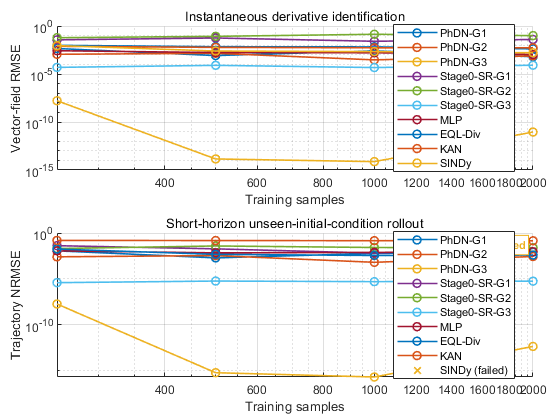

figSampleEfficiency = [];
sampleEfficiencyFigureData = struct();
sampleEfficiencyPlotError = '';
try
    [figSampleEfficiency,sampleEfficiencyFigureData] = ...
        plot_system_identification_sample_efficiency(systemIdentificationRows);
    if isgraphics(figSampleEfficiency)
        set(figSampleEfficiency,'Visible','on');
        figure(figSampleEfficiency);
        drawnow;
    else
        warning('Sample-efficiency plotting returned no valid figure.');
    end
catch MEsampleEfficiencyPlot
    sampleEfficiencyPlotError = getReport( ...
        MEsampleEfficiencyPlot,'extended','hyperlinks','off');
    warning('Sample-efficiency plotting failed');
    sampleEfficiencyFigureData = struct( ...
        'plotError',sampleEfficiencyPlotError, ...
        'generatedAt',char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')));
end


runMetadata = struct();
runMetadata.generatedAt = char(datetime('now','Format','yyyy-MM-dd HH:mm:ss'));
runMetadata.completeCaseWallTime = completeCaseWallTime;
runMetadata.trainingSampleList = TrainingSampleList;
runMetadata.nValidationSamples = NValidationSamples;
runMetadata.nIDTestSamples = NIDTestSamples;
runMetadata.numRounds = NumRounds;
runMetadata.samplingMethod = SamplingMethod;
runMetadata.sobolScrambleMethod = SobolScrambleMethod;
runMetadata.outputRoot = OutputCaseRoot;
runMetadata.recordedBaselineSourceRoot = RecordedBaselineSourceRoot;
runMetadata.recordedBaselineReplayStrict = RecordedBaselineReplayStrict;
runMetadata.methodPersistenceSchema = 'independent_method_record_v1';
runMetadata.methodPersistencePolicy = ...
    'per-method immediate checkpoint + non-destructive legacy/aggregate merge';
runMetadata.eqlPaperSampleEfficiencyProtocol = ...
    'exact_N_current_sample_training_with_adaptive_validation_search';
runMetadata.eqlPreviousModelRole = ...
    'fixed-Val target and optional current-N warm start; never unchanged substitution';
runMetadata.eqlAdaptiveSearch = struct( ...
    'warmStartPreviousModel',EQLWarmStartPreviousModel, ...
    'warmStartRestarts',EQLWarmStartRestarts, ...
    'rescueRestarts',EQLAdaptiveRescueRestarts, ...
    'rescueTopK',EQLAdaptiveRescueTopK, ...
    'strictRelativeMargin',EQLStrictImprovementRelativeMargin, ...
    'strictAbsoluteMargin',EQLStrictImprovementAbsoluteMargin, ...
    'targetOverridesDepthEarlyStop',EQLStrictTargetOverridesDepthEarlyStop);
runMetadata.phdnPriorAblation = struct( ...
    'G1',Stage0SRInitialGuesses_G1, ...
    'G2',Stage0SRInitialGuesses_G2, ...
    'G3',Stage0SRInitialGuesses_G3, ...
    'sindyMatchedLevel','G3', ...
    'includeStage0SRAblations',IncludeStage0SRAblationsInComparison, ...
    'stage0SRRolloutEnabled',struct( ...
        'G1',displayRecordReport_SR1, ...
        'G2',displayRecordReport_SR2, ...
        'G3',displayRecordReport_SR3));
runMetadata.displayRecordReport = struct( ...
    'PhDN_G1',displayRecordReport_PhDN_G1, ...
    'PhDN_G2',displayRecordReport_PhDN_G2, ...
    'PhDN_G3',displayRecordReport_PhDN_G3, ...
    'MLP',displayRecordReport_MLP,'EQL',displayRecordReport_EQL, ...
    'KAN',displayRecordReport_KAN,'SINDy',displayRecordReport_SINDy);
runMetadata.sampleEfficiencyPlotError = sampleEfficiencyPlotError;

if SaveResults
    summaryOutputInfo = save_single_generator_dynamic_summary_outputs( ...
        OutputSummaryDir,allResults,systemIdentificationRows,standardSummaryRows, ...
        sampleEfficiencyTable,figSampleEfficiency,sampleEfficiencyFigureData, ...
        runMetadata);
    ResultsFile = summaryOutputInfo.resultsMatPath;
    fprintf('Saved SingleGeneratorDynamic aggregate results to:\n%s\n',ResultsFile);
end






